# ROOT FINDING - BRACKETING METHOD

## BISECTION METHOD

function xr = bisection(xl, xu, it, f)
    % Initialize the arrays for root approximations and errors
    xr = zeros(it, 1);
    er = zeros(it, 1);

    for i = 2:it
        xr(i) = (xl + xu) / 2;

        fr = f(xr(i));
        fl = f(xl);
        fu = f(xu);

        if fr * fl < 0
            xu = xr(i);
        else
            xl = xr(i);
        end
        er(i) = abs((xr(i) - xr(i-1)) / xr(i)) * 100;
    end
end

fuc = @(x) exp(-x)-x;
xr = bisection(-2,2,100,fuc);
disp(xr(end));

## FALSE POSITION METHOD

function xr = false_position(xl, xu, it, f, er_total)
    if nargin < 5
        er_total = 0;
    end
    
    er = 1;
    xr = xl;
    xr_old = xl;
    i = 1;
    
    while er > er_total && i < it
        fl = f(xl);
        fu = f(xu);
        xr = (xu * fl - xl * fu) / (fl - fu);
        fr = f(xr);
        
        if fl * fr < 0
            xu = xr;
        else
            xl = xr;
        end
        
        er = abs((xr - xr_old) / xr);
        xr_old = xr;
        i = i + 1;
    end
end

fuc = @(x) exp(-x)-x;
xr = false_position(-2,2,100,fuc)

## FIXED POINT ITERATION

function x = fixed_point(x, it, g, er_total) %% g(x) = f(x)+x
    if nargin<4
        er_total = 0;
    end

    er = 1;
    x0 = x;
    i = 1;
    while er>er_total && i<it
        x = g(x0);
        er = abs((x-x0)/x);
        x0 = x;
        i = i+1;
    end
end

g = @(x) exp(-x);
xr = fixed_point(0,100,g)

## NEWTON RAPHSON METHOD

function x = newton_raphson(x, it, f, df, er_total)
    if nargin<5
        er_total = 0;
    end

    x0 = x;
    i = 1;
    er = 1;
    while er>er_total && i<it
        fx = f(x0);
        dfx = df(x0);
        x = x0 - fx/dfx;

        er = abs((x-x0)/x);
        x0 = x;
        i = i+1;
    end
end

fuc = @(x) exp(-x)-x;
dfuc = @(x) -exp(-x)-1;
xr = newton_raphson(0,100,fuc,dfuc)

## SECANT METHOD

function x = secant(a, b, it, f, er_total)
    if nargin<5
        er_total = 0;
    end

    i = 1;
    x0 = a;
    x1 = b;
    x = x1;
    er = 1;

    while er>er_total && i<it
        fx0 = f(x0);
        fx1 = f(x1);
        x = x1 - f(x1)*(x1 - x0)/(fx1 - fx0);
        er = abs((x-x1)/x);
        x0 = x1;
        x1 = x;
        i = i+1;
    end
end

fuc = @(x) exp(-x)-x;
xr = secant(0,10,100,fuc)

%%% coeff of variation = Sy/y_bar * 100, standard deviation Sy = (sum(yi-y_bar)^2/n-1)^0.5
%%% variance = Sy^2
%%% L = y_bar - sigma/(n)^0.5 * t(alpha/2,n-1)

## CURVE FITTING

## LEAST SQUARE REGRESSION

function [coeff, Syx, r2] = linear_regression(x, y)
    n = length(x);
    A = [n, sum(x); sum(x), sum(x.^2)];
    b = [sum(y); sum(x.*y)];

    coeff = A\b;
    a0 = coeff(1);
    a1 = coeff(2);

    yr = a0 + a1*x;
    e = y - yr;
    Sr = sum(e.^2);
    St = sum((y - mean(y)).^2);

    Syx = sqrt(Sr / (n - 2));
    r2 = (St - Sr) / St;
end
x = 1:1:7;
y = [0.5,2.5,2,4,3.5,6,5.5];
[coeff, Syx, r2] = linear_regression(x,y)

## QUADRATIC REGRESSION

function [coeff, Syx, r2] = quadratic_regression(x, y)
    n = length(x);
    A = [n, sum(x), sum(x.^2); sum(x), sum(x.^2), sum(x.^3); sum(x.^2), sum(x.^3), sum(x.^4)];
    b = [sum(y); sum(x.*y); sum(x.^2.*y)];

    coeff = A\b;
    a0 = coeff(1);
    a1 = coeff(2);
    a2 = coeff(3);

    yr = a0 + a1*x + a2*x.^2;
    
    e = y - yr;
    Sr = sum(e.^2);
    St = sum((y-mean(y)).^2);

    Syx = sqrt(Sr / (n-3));
    r2 = (St - Sr) / St;
end

x = 0:5;
y = [2.1 7.7 13.6 27.2 40.9 61.1];
[coeff, Syx, r2] = quadratic_regression(x,y)

## MULTIPLE LINEAR REGRESSION

function [coeff, Syx, r2] = multiple_linear_regression(x1, x2, y)
    n = length(y);

    A = [n, sum(x1), sum(x2); sum(x1), sum(x1.^2), sum(x1.*x2); sum(x2), sum(x1.*x2), sum(x2.^2)];
    b = [sum(y); sum(x1.*y); sum(x2.*y)];

    coeff = A\b;
    a0 = coeff(1);
    a1 = coeff(2);
    a2 = coeff(3);

    yr = a0 + a1*x1 + a2*x2;

    e = y - yr;
    Sr = sum(e.^2);
    St = sum((y - mean(y)).^2);

    Syx = sqrt(Sr / (n - 3));
    r2 = (St - Sr) / St;
end

x1 = [0 2 2.5 1 4 7];
x2 = [0 1 2 3 6 2];
y = [5 10 9 0 3 27];
[coeff, Sxy, r2] = multiple_linear_regression(x1, x2, y)

## NON-LINEAR REGRESSION

x = (0.25:0.5:2.25)';
y = [0.28 0.57 0.68 0.74 0.79]';
a0 = 1;
a1 = 1;
er = 1;
it = 1;
while er>1E-6 && it<101
    coeffl = [a0;a1];
    dfda0 = 1 - exp(-a1.*x);
    dfda1 = a0.*x.*exp(-a1.*x);
    Z = [dfda0 dfda1];
    A = Z'*Z;
    f = a0.*(1 - exp(-a1.*x));
    b = Z'*(y - f);
    da = A\b;
    coeff = coeffl + da;
    a0 = coeff(1);
    a1 = coeff(2);
    er = max(abs((coeff - coeffl)./coeff));
    it = it + 1;
end

disp(a0);
disp(a1);


## GENERAL LINEAR REGRESSION

function [coeff, R2] = general_linear_regression(x, y, poly)
    n = numel(x);
    Z = zeros(n, poly+1);
    b = zeros(poly+1, 1);
    
    % Construct design matrix Z
    for i = 1:poly+1
        Z(:,i) = x(:).^(i-1);
    end
    
    % Solve normal equations
    A = (Z' * Z);
    b = Z' * y;
    coeff = A \ b;
    
    % Compute predicted values
    y_pred = Z * coeff;
    
    % Compute R-squared (R²)
    SS_tot = sum((y - mean(y)).^2); % Total sum of squares
    SS_res = sum((y - y_pred).^2);  % Residual sum of squares
    R2 = 1 - (SS_res / SS_tot);
end

x = (0:5)';
y = [2.1 7.7 13.6 27.2 40.9 61.1]';
poly = 3; % Polynomial degree

[coeff, R2] = general_linear_regression(x, y, poly);

disp('Polynomial Coefficients:');
disp(coeff);
disp(['R-squared: ', num2str(R2)]);

## NEWTON INTERPOLATION

function [yp, coeff] = newton_interpolation(x, y, order, xp)
    % Finite difference table
    fd = zeros(order+1, order+1);
    
    % Fill the first column with y values
    fd(:,1) = y(1:order+1);
    
    % Compute divided differences (Newton's coefficients)
    for j = 2:order+1
        for i = 1:order+2-j
            fd(i,j) = (fd(i+1,j-1) - fd(i,j-1)) / (x(i+j-1) - x(i));
        end
    end
    
    % Extract coefficients (first row of finite difference table)
    coeff = fd(1, 1:order+1)';  
    
    % Newton interpolation formula
    yp = zeros(size(xp));  
    for k = 1:numel(xp)
        xt = 1;
        yp(k) = coeff(1);
        for i = 2:order+1
            xt = xt * (xp(k) - x(i-1));  % Product term
            yp(k) = yp(k) + coeff(i) * xt;
        end
    end
end

% Example Usage
x = [1 4 5 6 9 10]';
y = log(x);
xp = (1:0.1:10)';

% Compute interpolated values and coefficients
[yp, coeff] = newton_interpolation(x, y, 5, xp);

% Display results
disp('Newton Polynomial Coefficients:');
disp(coeff);


## LAGRANGE INTERPOLATION

function yp = lagrange_interpolation(x, y, xp)
    n = length(x);
    yp = 0;
    for i = 1:n
        mult = 1;
        for j = 1:n
            if j ~= i
                mult = mult * (xp - x(j)) / (x(i) - x(j));
            end
        end
        yp = yp + mult * y(i);
    end
end


## SPLINE INTERPOLATION

function yp = spline_interpolation(x,y,xp)
    n = length(x);
    i = 1;
    while x(i)<xp
        i = i+1;
    end
    u = i;
    l = i-1;
    yp = y(i-1)+(y(i)-y(i-1))*(xp-x(i-1))/(x(i)-x(i-1));
end

clc; clear;

% Define sample data
x = [1 2 3 4 5];  
y = [2 8 18 32 50];  

% Points to test interpolation
xp_test = [1.5, 2.5, 3.5, 4.5];

disp('Testing Lagrange Interpolation:');
for xp = xp_test
    yp_lagrange = lagrange_interpolation(x, y, xp);
    disp(['xp = ', num2str(xp), ', yp (Lagrange) = ', num2str(yp_lagrange)]);
end

disp('Testing Spline Interpolation:');
for xp = xp_test
    yp_spline = spline_interpolation(x, y, xp);
    disp(['xp = ', num2str(xp), ', yp (Spline) = ', num2str(yp_spline)]);
end


## INTEGRATION TECHNIQUES

## TRAPEZOID

function I = trapezoid(a, b, f, n)
    h = (b - a) / n;
    x = linspace(a, b, n+1);
    I = (f(x(1)) + 2 * sum(f(x(2:end-1))) + f(x(end))) * h / 2;
end

## SIMPSONS RULE

function I = simpson(a, b, f, n)
    if mod(n,2) ~= 0
        error('n must be even for Simpson’s Rule');
    end
    h = (b - a) / n;
    x = linspace(a, b, n+1);
    I = (h/3) * (f(x(1)) + 4 * sum(f(x(2:2:end))) + 2 * sum(f(x(3:2:end-1))) + f(x(end)));
end

test_func = @(x) x.^2;  % f(x) = x^2

% Integration limits
a = 0;
b = 2;
n_trap = 4;  % Trapezoidal: Any n works
n_simp = 6;  % Simpson: Must be even

% Compute integrals
I_trap = trapezoid(a, b, test_func, n_trap);
I_simp = simpson(a, b, test_func, n_simp);

% Display Results
fprintf('Trapezoidal Rule Approximation: %.6f\n', I_trap);
fprintf('Simpson’s Rule Approximation: %.6f\n', I_simp);


## MULTIPLE INTEGRATION

function Ixy = trapezoidal_double_integral(f, x_range, y_range, h)
    % Create meshgrid for x and y
    [X, Y] = meshgrid(x_range, y_range);
    
    % Evaluate function on grid
    F = f(X, Y);
    
    % Trapezoidal Rule for x-direction
    Ix = h/2 * (F(:,1) + 2*sum(F(:,2:end-1),2) + F(:,end));
    
    % Trapezoidal Rule for y-direction
    Ixy = h/2 * (Ix(1) + 2*sum(Ix(2:end-1)) + Ix(end));
end

% Define function f(x, y)
f = @(x, y) x + y;

% Define limits and step size
x_min = 0; x_max = 1;
y_min = 0; y_max = 2;
h = 0.1; % Step size

% Generate grid points
x_range = x_min:h:x_max;
y_range = y_min:h:y_max;

% Compute double integral using the function
Ixy = trapezoidal_double_integral(f, x_range, y_range, h);

% Display the result
fprintf('Double Integral Result: %.4f\n', Ixy);


## ROMBERG INTEGRATION

function [Rom, I] = romberg_integration(f, a, b)
    % Initialize parameters
    er = 1;
    it = 0;
    I = zeros(101, 101); % Preallocate a large matrix
    
    % Compute first approximation using a single trapezoidal step
    I(1,1) = trap(f, a, b, 1);
    
    % Iterative refinement using Romberg's method
    while er > 1E-10 && it < 100
        it = it + 1;
        n = 2^it;
        
        % Compute trapezoidal estimate with more intervals
        I(it+1,1) = trap(f, a, b, n);
        
        % Richardson extrapolation
        for k = 2:it+1
            j = 2 + it - k;
            I(j,k) = (4^(k-1) * I(j+1,k-1) - I(j,k-1)) / (4^(k-1) - 1);
        end
        
        % Compute relative error
        er = abs((I(1,it+1) - I(2,it)) / I(1,it+1));
    end
    
    % Final Romberg estimate
    Rom = I(1, it+1);
end

function [out] = trap(f, a, b, n)
    % Compute trapezoidal rule
    h = (b - a) / n;
    x = a:h:b;
    y = f(x);
    out = h/2 * (y(1) + 2*sum(y(2:end-1)) + y(end));
end

% Define the function to integrate
f = @(x) x + log(x);

% Integration limits
a = 1;
b = 2;

% Compute Romberg Integration
[Rom, I] = romberg_integration(f, a, b);

% Display the result
fprintf('Romberg Integral Result: %.10f\n', Rom);



## ADAPTIVE QUADRATURE

function [I, E] = adaptive_quadrature(f, a, b, tol)
    % Compute function values at key points
    c = (a + b) / 2;
    fa = f(a);
    fb = f(b);
    fc = f(c);
    
    % Call the recursive adaptive function
    [I, E] = adapt(f, a, b, tol, fa, fb, fc);
end

function [I, E] = adapt(f, a, b, tol, fa, fb, fc)
    h1 = b - a;
    h2 = h1 / 2;
    c = (a + b) / 2;
    d = (a + c) / 2;
    e = (c + b) / 2;
    
    % Evaluate function at new points
    fd = f(d);
    fe = f(e);
    
    % Compute Simpson's rule at two levels
    I1 = h1 / 6 * (fa + 4*fc + fb);  % Coarse estimate
    I2 = h2 / 6 * (fa + 4*fd + 2*fc + 4*fe + fb);  % Refined estimate
    
    % Error estimate
    E = abs(I1 - I2);
    
    if E < tol
        I = I2 + E / 15;  % Use corrected estimate
    else
        % Recursively refine the integration in subintervals
        [Ia, Ea] = adapt(f, a, c, tol, fa, fc, fd);
        [Ib, Eb] = adapt(f, c, b, tol, fc, fb, fe);
        I = Ia + Ib;
        E = max(Ea, Eb);
    end
end

% Define the function to integrate
f = @(x) x + log(x);

% Integration limits
a = 1;
b = 2;
tol = 1E-10; % Tolerance for adaptive refinement

% Compute Adaptive Quadrature
[I, E] = adaptive_quadrature(f, a, b, tol);

% Display the result
fprintf('Adaptive Quadrature Result: %.10f\n', I);
fprintf('Estimated Error: %.10e\n', E);

## NUMERICAL DIFFERENTIATION

function [fwd, bwd, cent] = numerical_differentiation(f, x, h)
    % Compute function values at necessary points
    f0 = f(x);
    f1 = f(x + h);
    f2 = f(x + 2*h);
    f3 = f(x + 3*h);
    f4 = f(x + 4*h);
    
    b1 = f(x - h);
    b2 = f(x - 2*h);
    b3 = f(x - 3*h);
    b4 = f(x - 4*h);
    
    % Forward Differences
    fwd = zeros(1,4);
    fwd(1) = (f1 - f0) / h;  % First derivative
    fwd(2) = (f2 - 2*f1 + f0) / h^2;  % Second derivative
    fwd(3) = (f3 - 3*f2 + 3*f1 - f0) / h^3;  % Third derivative
    fwd(4) = (f4 - 4*f3 + 6*f2 - 4*f1 + f0) / h^4;  % Fourth derivative

    % Backward Differences
    bwd = zeros(1,4);
    bwd(1) = (f0 - b1) / h;
    bwd(2) = (f0 - 2*b1 + b2) / h^2;
    bwd(3) = (f0 - 3*b1 + 3*b2 - b3) / h^3;
    bwd(4) = (f0 - 4*b1 + 6*b2 - 4*b3 + b4) / h^4;

    % Central Differences
    cent = zeros(1,4);
    cent(1) = (f1 - b1) / (2*h);
    cent(2) = (f1 - 2*f0 + b1) / h^2;
    cent(3) = (f2 - 2*f1 + 2*b1 - b2) / (2*h^3);
    cent(4) = (f2 - 4*f1 + 6*f0 - 4*b1 + b2) / h^4;
end

clc; clear; close all;

% Define function
f = @(x) sin(x);

% Point of differentiation
x = pi / 4;

% Step size
h = 0.01;

% Compute derivatives
[fwd, bwd, cent] = numerical_differentiation(f, x, h);

% Display results
fprintf('Forward Differences:\n');
fprintf('1st Derivative: %.5f\n', fwd(1));
fprintf('2nd Derivative: %.5f\n', fwd(2));
fprintf('3rd Derivative: %.5f\n', fwd(3));
fprintf('4th Derivative: %.5f\n', fwd(4));

fprintf('\nBackward Differences:\n');
fprintf('1st Derivative: %.5f\n', bwd(1));
fprintf('2nd Derivative: %.5f\n', bwd(2));
fprintf('3rd Derivative: %.5f\n', bwd(3));
fprintf('4th Derivative: %.5f\n', bwd(4));

fprintf('\nCentral Differences:\n');
fprintf('1st Derivative: %.5f\n', cent(1));
fprintf('2nd Derivative: %.5f\n', cent(2));
fprintf('3rd Derivative: %.5f\n', cent(3));
fprintf('4th Derivative: %.5f\n', cent(4));

## ALGEBRAIC SYSTEMS

## Gauss Elimination

% Guass Elimination Updated ( Version 1)
function x = gaussElimination(A, b)
n = size(A, 1);
Aug = [A, b];
for k = 1:n-1
    [~, maxIndex] = max(abs(Aug(k:n, k)));
    pivot = maxIndex + k - 1;
    if pivot ~= k
        Aug([k, pivot], :) = Aug([pivot, k], :);
    end
    for i = k+1:n
        factor = Aug(i, k) / Aug(k, k);
        Aug(i, k:end) = Aug(i, k:end) - factor * Aug(k, k:end);
    end
end
x = zeros(n, 1);
for i = n:-1:1
    x(i) = (Aug(i, end) - Aug(i, i+1:n) * x(i+1:n)) / Aug(i, i);
end
end

% Test example
A = [1 2 3; 3 8 5; 2 5 1];
b = [8; 12; 10];
x = gaussElimination(A, b);
disp(x);


% Guass Elimination Updated ( Version 2)
function x = gauss_elimination_scaled_pivoting(A, b)
    n = length(b);

    for k = 1:n-1
        % Pivoting
        [A, b] = pivot(A, b, k);
        
        % Scaling
        [A, b] = scale(A, b);
        
        % Forward Elimination
        for i = k+1:n
            fac = A(i, k) / A(k, k);
            A(i, k:n) = A(i, k:n) - fac * A(k, k:n);
            b(i) = b(i) - fac * b(k);
        end
    end

    % Back Substitution
    x = back_substitution(A, b);
end

%% Pivoting Function
function [A, b] = pivot(A, b, k)
    n = size(A, 1);
    p = k; % Initial pivot row
    big = abs(A(k, k));

    % Find the row with the maximum absolute value in column k
    for i = k+1:n
        dummy = abs(A(i, k));
        if dummy > big
            big = dummy;
            p = i;
        end
    end

    % Swap rows k and p if needed
    if p ~= k
        A([k, p], :) = A([p, k], :);
        b([k, p]) = b([p, k]);
    end
end

%% Scaling Function
function [A, b] = scale(A, b)
    n = size(A, 1);
    S = max(abs(A), [], 2); % Scaling factors

    for i = 1:n
        A(i, :) = A(i, :) / S(i);
        b(i) = b(i) / S(i);
    end
end

%% Back Substitution Function
function x = back_substitution(A, b)
    n = length(b);
    x = zeros(n, 1);
    x(n) = b(n) / A(n, n);

    for i = n-1:-1:1
        x(i) = (b(i) - A(i, i+1:n) * x(i+1:n)) / A(i, i);
    end
end

clc; clear; close all;
A = [1 2 3; 3 8 5; 2 5 1];
b = [8; 12; 10];

% Solve using Gauss Elimination with Scaling & Pivoting
x = gauss_elimination_scaled_pivoting(A, b);

disp('Solution:');
disp(x);

## Non-Linear Set of Equations

function x = newton_nonlinear(F, J, x0, tol, maxIter)
if nargin < 4, tol = 1e-8; end
if nargin < 5, maxIter = 100; end
x = x0;
for iter = 1:maxIter
    Fx = F(x);
    if norm(Fx) < tol
        fprintf('Converged in %d iterations.\n', iter);
        return;
    end
    Jx = J(x);
    delta = -Jx\Fx;
    x = x + delta;
    if norm(delta) < tol
        fprintf('Converged in %d iterations.\n', iter);
        return;
    end
end
fprintf('Maximum iterations reached.\n');
end
F = @(x) [x(1)^2 + x(2)^2 - 4;
          x(1)*x(2) - 1];
J = @(x) [2*x(1), 2*x(2);
          x(2),   x(1)];
x0 = [2; 0.5];  % initial guess
solution = newton_nonlinear(F, J, x0);
disp('Solution:');
disp(solution);


## Gauss Jordan Method


function X = gaussJordan(A, B)
[m, n] = size(A);
Aug = [A, B];
for i = 1:m
    [~, pivot] = max(abs(Aug(i:m, i)));
    pivot = pivot + i - 1;
    if pivot ~= i
        Aug([i, pivot], :) = Aug([pivot, i], :);
    end
    Aug(i, :) = Aug(i, :) / Aug(i, i);
    for j = 1:m
        if j ~= i
            Aug(j, :) = Aug(j, :) - Aug(j, i) * Aug(i, :);
        end
    end
end
X = Aug(:, n+1:end);
end

% Test example
A = [1 2 3; 3 8 5; 2 5 1];
B = [8; 12; 10];
X = gaussJordan(A, B);
disp(X);


## LU Decomposition

function x = luSolveNoLU(A, B)
    n = size(A, 1);
    L = eye(n);        % Initialize L as an identity matrix
    U = A;             % U starts as a copy of A
    P = eye(n);        % Permutation matrix

    % LU Decomposition with Partial Pivoting
    for k = 1:n-1
        % Find pivot row in column k (largest absolute value)
        [~, pivot] = max(abs(U(k:n, k)));
        pivot = pivot + k - 1;
        
        % Swap rows in U if pivot is not the current row
        if pivot ~= k
            U([k, pivot], :) = U([pivot, k], :);
            P([k, pivot], :) = P([pivot, k], :);
            if k > 1
                L([k, pivot], 1:k-1) = L([pivot, k], 1:k-1);
            end
        end
        
        % Elimination process: update L and U
        for i = k+1:n
            L(i, k) = U(i, k) / U(k, k);
            U(i, :) = U(i, :) - L(i, k) * U(k, :);
        end
    end

    % Forward substitution to solve L*y = P*B
    y = zeros(n, 1);
    PB = P * B;
    for i = 1:n
        y(i) = PB(i) - L(i, 1:i-1) * y(1:i-1);
    end

    % Backward substitution to solve U*x = y
    x = zeros(n, 1);
    for i = n:-1:1
        x(i) = (y(i) - U(i, i+1:n) * x(i+1:n)) / U(i, i);
    end
end

% Test Example
A = [1 2 3; 3 8 5; 2 5 1];
B = [8; 12; 10];
x = luSolveNoLU(A, B);
disp('Solution:');
disp(x);


## Crout's Method


function X = crout_LU_solver(A, B)
    % Function to solve AX = B using LU decomposition (Crout's method)
    % Inputs:
    %   A - Coefficient matrix (square)
    %   B - Right-hand side column vector
    % Output:
    %   X - Solution column vector

    [n, ~] = size(A);
    L = zeros(n, n);
    U = eye(n);
    
    % Crout's LU Decomposition
    for j = 1:n
        for i = j:n
            L(i, j) = A(i, j) - L(i, 1:j-1) * U(1:j-1, j);
        end
        for i = j+1:n
            U(j, i) = (A(j, i) - L(j, 1:j-1) * U(1:j-1, i)) / L(j, j);
        end
    end
    
    % Forward substitution to solve LY = B
    Y = zeros(n, 1);
    for i = 1:n
        Y(i) = (B(i) - L(i, 1:i-1) * Y(1:i-1)) / L(i, i);
    end
    
    % Backward substitution to solve UX = Y
    X = zeros(n, 1);
    for i = n:-1:1
        X(i) = Y(i) - U(i, i+1:n) * X(i+1:n);
    end
end
A = [1 2 3; 3 8 5; 2 5 1];
B = [8; 12; 10];
x = crout_LU_solver(A, B);
disp('Solution:');
disp(x);

## Doolite deComposition Method


function [X, L, U] = doolittle_LU_solver(A, B)
    % Function to solve AX = B using LU decomposition (Doolittle's method)
    % Inputs:
    %   A - Coefficient matrix (square)
    %   B - Right-hand side column vector
    % Outputs:
    %   X - Solution column vector
    %   L - Lower triangular matrix
    %   U - Upper triangular matrix

    [n, ~] = size(A);
    L = eye(n);
    U = zeros(n, n);
    
    % Doolittle's LU Decomposition
    for j = 1:n
        for i = 1:j
            U(i, j) = A(i, j) - L(i, 1:i-1) * U(1:i-1, j);
        end
        for i = j+1:n
            L(i, j) = (A(i, j) - L(i, 1:j-1) * U(1:j-1, j)) / U(j, j);
        end
    end
    
    % Display L and U matrices
    disp('Lower Triangular Matrix L:');
    disp(L);
    disp('Upper Triangular Matrix U:');
    disp(U);
    
    % Forward substitution to solve LY = B
    Y = zeros(n, 1);
    for i = 1:n
        Y(i) = (B(i) - L(i, 1:i-1) * Y(1:i-1));
    end
    
    % Backward substitution to solve UX = Y
    X = zeros(n, 1);
    for i = n:-1:1
        X(i) = (Y(i) - U(i, i+1:n) * X(i+1:n)) / U(i, i);
    end
end
A = [1 2 3; 3 8 5; 2 5 1];
B = [8; 12; 10];
x = doolittle_LU_solver(A, B);
disp('Solution:');
disp(x);


## Thomas Algorithm


function X = thomas_solver(A, B)
    % Solve AX = B where A is tridiagonal using Thomas Algorithm
    % Extract diagonals
    n = length(B);
    a = [0; diag(A, -1)]; % Sub-diagonal (a_2 to a_n)
    b = diag(A);          % Main diagonal (b_1 to b_n)
    c = [diag(A, 1); 0];  % Super-diagonal (c_1 to c_{n-1})
    d = B;
    
    % Forward elimination
    for i = 2:n
        w = a(i) / b(i-1);
        b(i) = b(i) - w * c(i-1);
        d(i) = d(i) - w * d(i-1);
    end
    
    % Back substitution
    X = zeros(n,1);
    X(n) = d(n) / b(n);
    for i = n-1:-1:1
        X(i) = (d(i) - c(i) * X(i+1)) / b(i);
    end
end

A = [1 2 3; 3 8 5; 2 5 1];
B = [8; 12; 10];
[x] = thomas_solver(A, B);
disp('Solution:');
disp(x);

% Cholesky Decomposition
function X = cholesky_solver(A, B)
    % Solve AX = B using Cholesky Decomposition without inbuilt functions
    % A must be symmetric and positive definite
    
    n = size(A, 1);
    L = zeros(n, n);
    
    % Compute the Cholesky decomposition A = L * L'
    for i = 1:n
        for j = 1:i
            sum = 0;
            for k = 1:j-1
                sum = sum + L(i, k) * L(j, k);
            end
            if i == j
                L(i, j) = sqrt(A(i, i) - sum);
            else
                L(i, j) = (A(i, j) - sum) / L(j, j);
            end
        end
    end
    
    % Solve L * Y = B using forward substitution
    Y = zeros(n,1);
    for i = 1:n
        sum = 0;
        for j = 1:i-1
            sum = sum + L(i, j) * Y(j);
        end
        Y(i) = (B(i) - sum) / L(i, i);
    end
    
    % Solve L' * X = Y using back substitution
    X = zeros(n,1);
    for i = n:-1:1
        sum = 0;
        for j = i+1:n
            sum = sum + L(j, i) * X(j);
        end
        X(i) = (Y(i) - sum) / L(i, i);
    end
end
A = [1 2 3; 3 8 5; 2 5 1];
B = [8; 12; 10];
[x] = cholesky_solver(A, B);
disp('Solution:');
disp(x);


## JACOBI SOLVER


function X = jacobi_solver(A, B, tol, max_iter)
    % Solve AX = B using Jacobi Iterative Method
    n = length(B);
    X = zeros(n,1);
    X_new = X;
    
    for iter = 1:max_iter
        for i = 1:n
            sum = 0;
            for j = 1:n
                if j ~= i
                    sum = sum + A(i, j) * X(j);
                end
            end
            X_new(i) = (B(i) - sum) / A(i, i);
        end
        
        if norm(X_new - X, inf) < tol
            break;
        end
        X = X_new;
    end
end


## GAUSS SEIDEL SOLVER


function X = gauss_seidel_solver(A, B, tol, max_iter)
    n = length(B);
    X = zeros(n,1);
    
    for iter = 1:max_iter
        X_old = X;
        for i = 1:n
            sum1 = 0;
            sum2 = 0;
            for j = 1:i-1
                sum1 = sum1 + A(i, j) * X(j);
            end
            for j = i+1:n
                sum2 = sum2 + A(i, j) * X_old(j);
            end
            X(i) = (B(i) - sum1 - sum2) / A(i, i);
        end
        
        if norm(X - X_old, inf) < tol
            break;
        end
    end
end

## **ODEs:**

**Euler method**

% Define the function f(x, y)
f = @(x, y) x + y;  % Example: dy/dx = x + y

% Initial conditions
x0 = 0;
y0 = 1;

% Step size and number of steps
h = 0.1;
n = 10;

% Initialize arrays manually
x(1) = x0;
y(1) = y0;

% Iteratively apply the formula y_{i+1} = y_i + f(x_i, y_i)*h
for i = 1:n
    phi = f(x(i), y(i));        % slope
    y(i+1) = y(i) + phi * h;    % new value
    x(i+1) = x(i) + h;          % update x
end

plot(x, y, 'bo-', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Euler Method Solution of dy/dx = x + y');
grid on;



% Analytical solution
x_exact = linspace(0, 1, 100);
y_exact = 2 * exp(x_exact) - x_exact - 1;

% Plot both
plot(x, y, 'bo-', 'LineWidth', 2); hold on;
plot(x_exact, y_exact, 'r--', 'LineWidth', 2);
legend('Euler Method', 'Exact Solution');
xlabel('x'); ylabel('y');
title('Euler Method vs. Exact Solution');
grid on;



% Exact solution at the Euler points
y_true = 2 * exp(x) - x - 1;
error = abs(y - y_true);

% Plot the error
figure;
plot(x, error, 'k*-', 'LineWidth', 1.5);
xlabel('x');
ylabel('Error |y_{Euler} - y_{Exact}|');
title('Error in Euler Method');
grid on;

%%%%
%%Euler's Method for Solving ODEs

%%Problem: Solve the first-order ODE:
%%dydx=f(x,y),y(x0)=y0
%%dxdy�=f(x,y),y(x0�)=y0�

% using Euler's Method.
% 1. Mathematical Formulation
% 
% Euler's method approximates the solution using:
% yn+1=yn+h⋅f(xn,yn)
% yn+1�=yn�+h⋅f(xn�,yn�)
% 
% where:
% 
%     hh = step size
% 
%     f(xn,yn)f(xn�,yn�) = slope at (xn,yn)(xn�,yn�)
% 
%     (xn+1,yn+1)(xn+1�,yn+1�) = next approximation.
% 
% 2. Explanation
% 
%     Initial Condition: Start at (x0,y0)(x0�,y0�).
% 
%     Iterative Update:
% 
%         Compute slope ϕ=f(xn,yn)ϕ=f(xn�,yn�).
% 
%         Update yn+1=yn+h⋅ϕyn+1�=yn�+h⋅ϕ.
% 
%         Move to xn+1=xn+hxn+1�=xn�+h.
% 
%     Stops after nn steps.
% 
% 3. Pseudocode
% plaintext
% 
% 1. Define f(x, y) = dy/dx
% 2. Input: x0, y0, h, n
% 3. Initialize x(1) = x0, y(1) = y0
% 4. For i = 1 to n:
% 5.    phi = f(x(i), y(i))       % Compute slope
% 6.    y(i+1) = y(i) + h * phi   % Update y
% 7.    x(i+1) = x(i) + h         % Update x
% 8. Return x, y
% 
% 4. Dry Run Example
% 
% Given:
% 
%     f(x,y)=x+yf(x,y)=x+y
% 
%     x0=0,y0=1x0�=0,y0�=1
% 
%     h=0.1,n=3h=0.1,n=3
% 
% Iteration (i)	xixi�	yiyi�	ϕ=f(xi,yi)ϕ=f(xi�,yi�)	yi+1=yi+h⋅ϕyi+1�=yi�+h⋅ϕ
% 1	0.0	1.0	0+1=10+1=1	1+0.1⋅1=1.11+0.1⋅1=1.1
% 2	0.1	1.1	0.1+1.1=1.20.1+1.1=1.2	1.1+0.1⋅1.2=1.221.1+0.1⋅1.2=1.22
% 3	0.2	1.22	0.2+1.22=1.420.2+1.22=1.42	1.22+0.1⋅1.42=1.3621.22+0.1⋅1.42=1.362
% 
% Final Output:
% (x,y)=([0,0.1,0.2,0.3],[1,1.1,1.22,1.362])
% (x,y)=([0,0.1,0.2,0.3],[1,1.1,1.22,1.362])
%%%%

Euler Method for 2 Order equation 

% Define the system of ODEs
f1 = @(x, y1, y2) y2;               % dy1/dx = y2
f2 = @(x, y1, y2) -2*y2 - y1;       % dy2/dx = -2*y2 - y1

% Initial conditions
x0 = 0;
y1_0 = 1;     % y(0)
y2_0 = 0;     % y'(0)

% Step size and number of steps
h = 0.1;
n = 10;

% Initialize arrays
x = zeros(1, n+1);
y1 = zeros(1, n+1);
y2 = zeros(1, n+1);

% Set initial values
x(1) = x0;
y1(1) = y1_0;
y2(1) = y2_0;

% Euler iteration
for i = 1:n
    y1(i+1) = y1(i) + h * f1(x(i), y1(i), y2(i));
    y2(i+1) = y2(i) + h * f2(x(i), y1(i), y2(i));
    x(i+1) = x(i) + h;
end

% Plot numerical solution
plot(x, y1, 'bo-', 'LineWidth', 2); hold on;
xlabel('x'); ylabel('y');
title('Euler Method for 2nd Order ODE');
grid on;

% (Optional) Analytical solution: y = exp(-x)
y_exact = exp(-x);
plot(x, y_exact, 'r--', 'LineWidth', 2);
legend('Euler Method', 'Exact Solution');

% Error plot
figure;
error = abs(y1 - y_exact);
plot(x, error, 'k*-', 'LineWidth', 1.5);
xlabel('x');
ylabel('Error |y_{Euler} - y_{Exact}|');
title('Error in Euler Method for 2nd Order ODE');
grid on;



% 🔍 PROBLEM STATEMENT
% 
% We are solving a second-order differential equation:
% d2ydx2=−2dydx−y
% dx2d2y�=−2dxdy�−y
% 
% With initial conditions:
% y(0)=1,y′(0)=0
% y(0)=1,y′(0)=0
% 🔁 CONVERSION TO FIRST ORDER SYSTEM
% 
% Let:
% 
%     y1=yy1�=y
% 
%     y2=dydxy2�=dxdy�
% 
% Then:
% 
%     dy1dx=y2dxdy1��=y2�
% 
%     dy2dx=−2y2−y1dxdy2��=−2y2�−y1�
% 
% Now we solve this system of first-order ODEs using the Euler method.
% 🧠 EXPLANATION
% 
% Euler’s method for first-order ODE:
% yi+1=yi+h⋅f(xi,yi)
% yi+1�=yi�+h⋅f(xi�,yi�)
% 
% Here, for two equations:
% 
%     y1i+1=y1i+h⋅y2iy1i+1�=y1i�+h⋅y2i�
% 
%     y2i+1=y2i+h⋅(−2y2i−y1i)y2i+1�=y2i�+h⋅(−2y2i�−y1i�)
% 
%     xi+1=xi+hxi+1�=xi�+h
% 
% 🧾 PSEUDOCODE (Format: Your Style)
% 
% Given:
%     f1(x, y1, y2) = y2
%     f2(x, y1, y2) = -2*y2 - y1
%     Initial conditions: x0, y1_0, y2_0
%     Step size: h
%     Number of steps: n
% 
% Algorithm:
% 1. Initialize arrays x[0 to n], y1[0 to n], y2[0 to n]
% 2. Set x[0] = x0, y1[0] = y1_0, y2[0] = y2_0
% 3. For i = 0 to n-1:
%        x[i+1] = x[i] + h
%        y1[i+1] = y1[i] + h * f1(x[i], y1[i], y2[i])
%        y2[i+1] = y2[i] + h * f2(x[i], y1[i], y2[i])
% 4. End For
% 5. Output x[], y1[] as numerical solution
% 
% 📊 DRY RUN (First 3 Steps)
% 
% Let:
% 
%     x0=0x0�=0, y1(0)=1y1�(0)=1, y2(0)=0y2�(0)=0
% 
%     h=0.1h=0.1, n=3n=3
% 
% Step (i)	x(i)	y1(i)	y2(i)	f1 = y2(i)	f2 = -2*y2 - y1	y1(i+1) = y1 + h*f1	y2(i+1) = y2 + h*f2
% 0	0.0	1.0000	0.0000	0.0000	-1.0000	1.0000	-0.1000
% 1	0.1	1.0000	-0.1000	-0.1000	-1.0000	0.9900	-0.2000
% 2	0.2	0.9900	-0.2000	-0.2000	-0.9900	0.9700	-0.2990
% 
% Explanation of row 1:
% 
%     y1(1)=1+0.1⋅0=1.0y1�(1)=1+0.1⋅0=1.0
% 
%     y2(1)=0+0.1⋅(−1)=−0.1y2�(1)=0+0.1⋅(−1)=−0.1

**Heun's Method**

% Define the function f(x, y)
f = @(x, y) x + y;  % Example: dy/dx = x + y

% Initial conditions
x0 = 0;
y0 = 1;

% Step size and number of steps
h = 0.1;
n = 10;

% Initialize arrays
x(1) = x0;
y(1) = y0;

% Apply Heun's Method
for i = 1:n
    % Predictor step (Euler's estimate)
    y_pred = y(i) + h * f(x(i), y(i));
    
    % Next x
    x(i+1) = x(i) + h;

    % Corrector step
    y(i+1) = y(i) + (h/2) * (f(x(i), y(i)) + f(x(i+1), y_pred));
end

% Display results
for i = 1:(n+1)
    fprintf('x = %.2f, y = %.4f\n', x(i), y(i));
end

x = 0.00, y = 1.0000
x = 0.10, y = 1.1100
x = 0.20, y = 1.2421
x = 0.30, y = 1.3985
x = 0.40, y = 1.5818
x = 0.50, y = 1.7949
x = 0.60, y = 2.0409
x = 0.70, y = 2.3231
x = 0.80, y = 2.6456
x = 0.90, y = 3.0124
x = 1.00, y = 3.4282




plot(x, y, 'bo-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('Heun''s Method Solution of dy/dx = x + y');
grid on;


% Exact solution
x_exact = linspace(0, 1, 100);
y_exact = 2 * exp(x_exact) - x_exact - 1;

% Plot Heun's vs Exact
plot(x, y, 'bo-', 'LineWidth', 2); hold on;
plot(x_exact, y_exact, 'r--', 'LineWidth', 2);
legend('Heun''s Method', 'Exact Solution');
xlabel('x'); ylabel('y');
title('Heun''s Method vs. Exact Solution');
grid on;


y_true = 2 * exp(x) - x - 1;
error = abs(y - y_true);

% Plot error
figure;
plot(x, error, 'k*-', 'LineWidth', 1.5);
xlabel('x');
ylabel('Error |y_{Heun} - y_{Exact}|');
title('Error in Heun''s Method');
grid on;


%  Explanation: Heun's Method (Improved Euler)
% 
% Heun’s method is a predictor-corrector technique for solving first-order ordinary differential equations (ODEs) of the form:
% dydx=f(x,y),y(x0)=y0
% dxdy�=f(x,y),y(x0�)=y0�
% 
% Instead of using just the slope at the beginning of the interval (like Euler), Heun uses an average slope between:
% 
%     The initial slope f(xi,yi)f(xi�,yi�)
% 
%     And a predicted slope at (xi+1,ypred)(xi+1�,ypred�)
% 
% This makes it a 2nd-order accurate method.
% %%%%%%%%%%Formula:
% 
%     Predictor step (Euler's estimate):
% 
% ypred=yi+h⋅f(xi,yi)
% ypred�=yi�+h⋅f(xi�,yi�)
% 
%     Corrector step:
% 
% yi+1=yi+h2⋅[f(xi,yi)+f(xi+1,ypred)]
% yi+1�=yi�+2h�⋅[f(xi�,yi�)+f(xi+1�,ypred�)]
% %%%%%%%%%Pseudocode
% 
% Function HeunMethod(f, x0, y0, h, n):
%     Initialize x[0] = x0
%     Initialize y[0] = y0
% 
%     For i = 0 to n-1:
%         x[i+1] = x[i] + h
% 
%         // Predictor step
%         y_pred = y[i] + h * f(x[i], y[i])
% 
%         // Corrector step
%         slope_avg = (f(x[i], y[i]) + f(x[i+1], y_pred)) / 2
%         y[i+1] = y[i] + h * slope_avg
% 
%     Return x[], y[]
% 
% 🔎 Dry Run
% 
% Let’s do the first 2 steps for your problem:
% 
%     ODE: dydx=x+ydxdy�=x+y
% 
%     Initial: x0=0,y0=1x0�=0,y0�=1
% 
%     Step size: h=0.1h=0.1
% 
% 🔹 Step 1: i=0i=0
% 
%     x0=0x0�=0, y0=1y0�=1
% 
%     Predictor:
%     f(x0,y0)=0+1=1
%     f(x0�,y0�)=0+1=1
%     ypred=1+0.1⋅1=1.1
%     ypred�=1+0.1⋅1=1.1
% 
%     Corrector:
%     f(x1,ypred)=0.1+1.1=1.2
%     f(x1�,ypred�)=0.1+1.1=1.2
%     y1=1+0.12⋅(1+1.2)=1+0.05⋅2.2=1.11
%     y1�=1+20.1�⋅(1+1.2)=1+0.05⋅2.2=1.11
% 
%     Update: x1=0.1x1�=0.1, y1=1.11y1�=1.11
% 
% 🔹 Step 2: i=1i=1
% 
%     x1=0.1x1�=0.1, y1=1.11y1�=1.11
% 
%     Predictor:
%     f=0.1+1.11=1.21
%     f=0.1+1.11=1.21
%     ypred=1.11+0.1⋅1.21=1.231
%     ypred�=1.11+0.1⋅1.21=1.231
% 
%     Corrector:
%     f(x2,ypred)=0.2+1.231=1.431
%     f(x2�,ypred�)=0.2+1.231=1.431
%     y2=1.11+0.05⋅(1.21+1.431)=1.11+0.05⋅2.641=1.2421
%     y2�=1.11+0.05⋅(1.21+1.431)=1.11+0.05⋅2.641=1.2421
% 
%     Update: x2=0.2x2�=0.2, y2≈1.2421y2�≈1.2421

**Midpoint (Improved Polygon) method Or RK2**

% Define the function f(x, y)
f = @(x, y) x + y;  % Example: dy/dx = x + y

% Initial conditions
x0 = 0;
y0 = 1;

% Step size and number of steps
h = 0.1;
n = 10;

% Initialize arrays
x(1) = x0;
y(1) = y0;

% Apply Midpoint Method
for i = 1:n
    y_half = y(i) + h * f(x(i), y(i))/2;
    
    % Next x
    x_half = x(i) + h/2;

    % Corrector step
    y(i+1) = y(i) + h * f(x_half, y_half);
end

% Display results
for i = 1:(n+1)
    fprintf('x = %.2f, y = %.4f\n', x(i), y(i));
end

x = 0.00, y = 1.0000
x = 0.10, y = 1.1100
x = 0.20, y = 1.2421
x = 0.30, y = 1.3985
x = 0.40, y = 1.5818
x = 0.50, y = 1.7949
x = 0.60, y = 2.0409
x = 0.70, y = 2.3231
x = 0.80, y = 2.6456
x = 0.90, y = 3.0124
x = 1.00, y = 3.4282



x_exact = linspace(0, 1, 100);
y_exact = 2 * exp(x_exact) - x_exact - 1;

plot(x, y, 'bo-', 'LineWidth', 2); hold on;
plot(x_exact, y_exact, 'r--', 'LineWidth', 2);
legend('Midpoint Method', 'Exact Solution');
xlabel('x'); ylabel('y');
title('Midpoint Method vs. Exact Solution');
grid on;


y_true = 2 * exp(x) - x - 1;
error = abs(y - y_true);

figure;
plot(x, error, 'k*-', 'LineWidth', 1.5);
xlabel('x'); ylabel('Error');
title('Error in Midpoint Method');
grid on;



%  Explanation: Midpoint Method (RK2)
% 
% The Midpoint Method estimates the next value yi+1yi+1� by:
% 
%     Predicting the solution at the midpoint of the interval
% 
%     Using the slope at that midpoint to advance the full step
% 
% 🔁 Formula:
% k1=f(xi,yi)
% k1�=f(xi�,yi�)
% k2=f(xi+h2, yi+h2⋅k1)
% k2�=f(xi�+2h�, yi�+2h�⋅k1�)
% yi+1=yi+h⋅k2
% yi+1�=yi�+h⋅k2�
% 🧠 Pseudocode
% 
% Function MidpointMethod(f, x0, y0, h, n):
%     Initialize x[0] = x0
%     Initialize y[0] = y0
% 
%     For i = 0 to n-1:
%         k1 = f(x[i], y[i])
%         x_half = x[i] + h/2
%         y_half = y[i] + (h/2) * k1
%         k2 = f(x_half, y_half)
% 
%         x[i+1] = x[i] + h
%         y[i+1] = y[i] + h * k2
% 
%     Return x[], y[]
% 
% 🔎 Dry Run (First 2 Steps)
% ODE: dydx=x+ydxdy�=x+y
% 
% Initial: x0=0, y0=1x0�=0, y0�=1
% Step size: h=0.1h=0.1
% 🔹 Step 1: i=0i=0
% 
%     x0=0, y0=1x0�=0, y0�=1
% 
%     k1=f(0,1)=0+1=1k1�=f(0,1)=0+1=1
% 
%     Midpoint:
% 
%         xmid=0.05xmid�=0.05
% 
%         ymid=1+0.1/2⋅1=1.05ymid�=1+0.1/2⋅1=1.05
% 
%     k2=f(0.05,1.05)=0.05+1.05=1.10k2�=f(0.05,1.05)=0.05+1.05=1.10
% 
%     y1=1+0.1⋅1.10=1.11y1�=1+0.1⋅1.10=1.11
% 
%     x1=0.1x1�=0.1
% 
% ✅ Same value as Heun’s method at this step (they both are RK2 methods, just slightly different logic)
% 🔹 Step 2: i=1i=1
% 
%     x1=0.1, y1=1.11x1�=0.1, y1�=1.11
% 
%     k1=f(0.1,1.11)=0.1+1.11=1.21k1�=f(0.1,1.11)=0.1+1.11=1.21
% 
%     Midpoint:
% 
%         xmid=0.15xmid�=0.15
% 
%         ymid=1.11+0.05⋅1.21=1.1705ymid�=1.11+0.05⋅1.21=1.1705
% 
%     k2=f(0.15,1.1705)=0.15+1.1705=1.3205k2�=f(0.15,1.1705)=0.15+1.1705=1.3205
% 
%     y2=1.11+0.1⋅1.3205=1.24205y2�=1.11+0.1⋅1.3205=1.24205
% 
%     x2=0.2x2�=0.2

## Runge Kutta Method (RK2)

% Define the function f(x, y)
f = @(x, y) x + y;  % Example: dy/dx = x + y

% Initial conditions
x0 = 0;
y0 = 1;

% Step size and number of steps
h = 0.1;
n = 10;

% Initialize arrays
x(1) = x0;
y(1) = y0;

% RK2 Loop (Midpoint Method)
for i = 1:n
    k1 = f(x(i), y(i));
    k2 = f(x(i) + h/2, y(i) + (h/2) * k1);
    
    y(i+1) = y(i) + h * k2;
    x(i+1) = x(i) + h;
end

% Display results
for i = 1:(n+1)
    fprintf('x = %.2f, y = %.4f\n', x(i), y(i));
end

x = 0.00, y = 1.0000
x = 0.10, y = 1.1100
x = 0.20, y = 1.2421
x = 0.30, y = 1.3985
x = 0.40, y = 1.5818
x = 0.50, y = 1.7949
x = 0.60, y = 2.0409
x = 0.70, y = 2.3231
x = 0.80, y = 2.6456
x = 0.90, y = 3.0124
x = 1.00, y = 3.4282




% Exact solution
x_exact = linspace(0, 1, 100);
y_exact = 2 * exp(x_exact) - x_exact - 1;

% Plot
plot(x, y, 'bo-', 'LineWidth', 2); hold on;
plot(x_exact, y_exact, 'r--', 'LineWidth', 2);
legend('RK2 (Midpoint)', 'Exact Solution');
xlabel('x'); ylabel('y');
title('RK2 (Midpoint) vs Exact');
grid on;


y_true = 2 * exp(x) - x - 1;
error = abs(y - y_true);

figure;
plot(x, error, 'k*-');
xlabel('x'); ylabel('Error');
title('RK2 (Midpoint) Method Error');
grid on;


%  Explanation: RK2 (Midpoint Version)
% 
% This method improves over Euler by sampling the slope at the midpoint and using that to update the solution. It gives second-order accuracy.
% 🔁 Update Equations:
% k1=f(xi,yi)
% k1�=f(xi�,yi�)
% k2=f(xi+h2, yi+h2⋅k1)
% k2�=f(xi�+2h�, yi�+2h�⋅k1�)
% yi+1=yi+h⋅k2
% yi+1�=yi�+h⋅k2�
% xi+1=xi+h
% xi+1�=xi�+h
% 🧠 Pseudocode
% 
% Function RK2_Midpoint(f, x0, y0, h, n):
%     Initialize x[0] = x0
%     Initialize y[0] = y0
% 
%     For i = 0 to n-1:
%         k1 = f(x[i], y[i])
%         k2 = f(x[i] + h/2, y[i] + h/2 * k1)
% 
%         y[i+1] = y[i] + h * k2
%         x[i+1] = x[i] + h
% 
%     Return x, y
% 
% 🔎 Dry Run (Step-by-step)
% 
% Given:
% 
%     dydx=x+ydxdy�=x+y
% 
%     Initial: x0=0, y0=1x0�=0, y0�=1
% 
%     Step size: h=0.1h=0.1
% 
% 🔹 Step 1: i=0i=0
% 
%     x0=0, y0=1x0�=0, y0�=1
% 
%     k1=f(0,1)=1k1�=f(0,1)=1
% 
%     Midpoint:
% 
%         x=0.05x=0.05, y=1+0.05=1.05y=1+0.05=1.05
% 
%     k2=f(0.05,1.05)=1.10k2�=f(0.05,1.05)=1.10
% 
%     y1=1+0.1⋅1.10=1.11y1�=1+0.1⋅1.10=1.11
% 
%     x1=0.1x1�=0.1
% 
% ✅ Same as Midpoint and Heun’s first step!
% 🔹 Step 2: i=1i=1
% 
%     x=0.1, y=1.11x=0.1, y=1.11
% 
%     k1=0.1+1.11=1.21k1�=0.1+1.11=1.21
% 
%     Midpoint x=0.15x=0.15, y=1.11+0.05⋅1.21=1.1705y=1.11+0.05⋅1.21=1.1705
% 
%     k2=0.15+1.1705=1.3205k2�=0.15+1.1705=1.3205
% 
%     y2=1.11+0.1⋅1.3205=1.24205y2�=1.11+0.1⋅1.3205=1.24205

## RK4

% Define the function f(x, y)
f = @(x, y) x + y;  % Example: dy/dx = x + y

% Initial conditions
x0 = 0;
y0 = 1;

% Step size and number of steps
h = 0.1;
n = 10;

% Initialize arrays
x(1) = x0;
y(1) = y0;

% RK4 Loop
for i = 1:n
    k1 = f(x(i), y(i));
    k2 = f(x(i) + h/2, y(i) + (h/2) * k1);
    k3 = f(x(i) + h/2, y(i) + (h/2) * k2);
    k4 = f(x(i) + h,   y(i) + h * k3);
    
    y(i+1) = y(i) + (h/6) * (k1 + 2*k2 + 2*k3 + k4);
    x(i+1) = x(i) + h;
end

% Display results
for i = 1:(n+1)
    fprintf('x = %.2f, y = %.4f\n', x(i), y(i));
end

x = 0.00, y = 1.0000
x = 0.10, y = 1.1103
x = 0.20, y = 1.2428
x = 0.30, y = 1.3997
x = 0.40, y = 1.5836
x = 0.50, y = 1.7974
x = 0.60, y = 2.0442
x = 0.70, y = 2.3275
x = 0.80, y = 2.6511
x = 0.90, y = 3.0192
x = 1.00, y = 3.4366



x_exact = linspace(0, 1, 100);
y_exact = 2 * exp(x_exact) - x_exact - 1;

plot(x, y, 'bo-', 'LineWidth', 2); hold on;
plot(x_exact, y_exact, 'r--', 'LineWidth', 2);
legend('RK4', 'Exact Solution');
xlabel('x'); ylabel('y');
title('RK4 vs. Exact Solution');
grid on;


y_true = 2 * exp(x) - x - 1;
error = abs(y - y_true);

figure;
plot(x, error, 'k*-');
xlabel('x'); ylabel('Error');
title('RK4 Method Error');
grid on;


% Explanation: RK4 Method
% 
% RK4 improves accuracy by sampling the slope at 4 locations within each step and taking a weighted average.
% 🔁 Formula:
% k1=f(xi,yi)
% k1�=f(xi�,yi�)
% k2=f(xi+h2,yi+h2⋅k1)
% k2�=f(xi�+2h�,yi�+2h�⋅k1�)
% k3=f(xi+h2,yi+h2⋅k2)
% k3�=f(xi�+2h�,yi�+2h�⋅k2�)
% k4=f(xi+h,yi+h⋅k3)
% k4�=f(xi�+h,yi�+h⋅k3�)
% yi+1=yi+h6(k1+2k2+2k3+k4)
% yi+1�=yi�+6h�(k1�+2k2�+2k3�+k4�)
% 🧠 Pseudocode
% 
% Function RK4(f, x0, y0, h, n):
%     Initialize x[0] = x0
%     Initialize y[0] = y0
% 
%     For i = 0 to n-1:
%         k1 = f(x[i], y[i])
%         k2 = f(x[i] + h/2, y[i] + h/2 * k1)
%         k3 = f(x[i] + h/2, y[i] + h/2 * k2)
%         k4 = f(x[i] + h,   y[i] + h * k3)
% 
%         y[i+1] = y[i] + h/6 * (k1 + 2*k2 + 2*k3 + k4)
%         x[i+1] = x[i] + h
% 
%     Return x, y
% 
% 🔎 Dry Run (First Step)
% Given:
% 
% dydx=x+ydxdy�=x+y
% x0=0, y0=1x0�=0, y0�=1
% h=0.1h=0.1
% 🔹 Step 1: i=0i=0
% 
%     k1=f(0,1)=0+1=1k1�=f(0,1)=0+1=1
% 
%     k2=f(0.05,1.05)=0.05+1.05=1.10k2�=f(0.05,1.05)=0.05+1.05=1.10
% 
%     k3=f(0.05,1.055)=0.05+1.055=1.105k3�=f(0.05,1.055)=0.05+1.055=1.105
% 
%     k4=f(0.1,1.1105)=0.1+1.1105=1.2105k4�=f(0.1,1.1105)=0.1+1.1105=1.2105
% 
% y1=1+0.16(1+2⋅1.10+2⋅1.105+1.2105)=1+0.16(6.6205)=1+0.1103=1.1103
% y1�=1+60.1�(1+2⋅1.10+2⋅1.105+1.2105)=1+60.1�(6.6205)=1+0.1103=1.1103�
% 
% ✅ RK4 is more accurate than RK2 and Heun's method even at small step sizes.

%% All Rk methods are the same, just check the values used in the calculations for K1, K2, K3, K4, etc from the notes


Second Order ODE 

% Define the second order ODE as a system of first order equations
% Let v = y', then the system is:
% y' = v
% v' = f(t, y, v)
f = @(t, y, v) -y;  % Example: y'' + y = 0 (simple harmonic oscillator)

% Initial conditions
t0 = 0;
y0 = 1;     % Initial position
v0 = 0;     % Initial velocity

% Step size and number of steps
h = 0.1;
n = 100;

% Initialize arrays
t = zeros(1, n+1);
y = zeros(1, n+1);
v = zeros(1, n+1);

t(1) = t0;
y(1) = y0;
v(1) = v0;

% RK4 Loop for second order ODE
for i = 1:n
    % First set of slopes (k1, l1)
    k1 = v(i);
    l1 = f(t(i), y(i), v(i));
    
    % Second set of slopes (k2, l2)
    k2 = v(i) + (h/2)*l1;
    l2 = f(t(i) + h/2, y(i) + (h/2)*k1, v(i) + (h/2)*l1);
    
    % Third set of slopes (k3, l3)
    k3 = v(i) + (h/2)*l2;
    l3 = f(t(i) + h/2, y(i) + (h/2)*k2, v(i) + (h/2)*l2);
    
    % Fourth set of slopes (k4, l4)
    k4 = v(i) + h*l3;
    l4 = f(t(i) + h, y(i) + h*k3, v(i) + h*l3);
    
    % Update y and v
    y(i+1) = y(i) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    v(i+1) = v(i) + (h/6)*(l1 + 2*l2 + 2*l3 + l4);
    t(i+1) = t(i) + h;
end

% Plot the solution
figure;
plot(t, y, 'b-', 'LineWidth', 2);
hold on;
plot(t, v, 'r--', 'LineWidth', 2);
xlabel('Time (t)');
ylabel('Solution');
legend('Position (y)', 'Velocity (v)');
title('RK4 Solution for Second Order ODE');
grid on;

% Compare with exact solution (for y'' + y = 0, y(0)=1, y'(0)=0)
y_exact = cos(t);
error = abs(y - y_exact);
figure;
plot(t, error, 'k-');
xlabel('Time (t)');
ylabel('Error');
title('Numerical Error');
grid on;

## Adaptive RK

% Function definition: dy/dx = f(x, y)
f = @(x, y) x + y;

% Initial conditions
x0 = 0;
y0 = 1;
x_end = 1;

% Initial step size and tolerance
h = 0.1;
tol = 1e-4;
h_min = 1e-4;
h_max = 0.2;

% Initialize arrays
x(1) = x0;
y(1) = y0;
i = 1;

while x(i) < x_end
    if x(i) + h > x_end
        h = x_end - x(i);  % Avoid overshooting
    end

    % RK2 estimate
    k1 = f(x(i), y(i));
    k2 = f(x(i) + h, y(i) + h * k1);
    y2 = y(i) + (h/2) * (k1 + k2);  % 2nd-order

    % RK3 estimate
    k1 = f(x(i), y(i));
    k2 = f(x(i) + h/2, y(i) + h/2 * k1);
    k3 = f(x(i) + h, y(i) - h * k1 + 2 * h * k2);
    y3 = y(i) + (h/6) * (k1 + 4 * k2 + k3);  % 3rd-order

    % Estimate local error
    err = abs(y3 - y2);

    if err < tol
        % Accept the step
        x(i+1) = x(i) + h;
        y(i+1) = y3;
        i = i + 1;
    end

    % Update step size
    if err == 0
        h = h_max;
    else
        h = 0.9 * h * (tol / err)^(1/3);
        h = max(min(h, h_max), h_min);  % Clamp h within [h_min, h_max]
    end
end

% Display results
for j = 1:length(x)
    fprintf('x = %.5f, y = %.6f\n', x(j), y(j));
end

x = 0.00000, y = 1.000000
x = 0.06025, y = 1.063952
x = 0.12050, y = 1.135617
x = 0.17955, y = 1.213802
x = 0.23743, y = 1.298531
x = 0.29417, y = 1.389856
x = 0.34984, y = 1.487832
x = 0.40446, y = 1.592519
x = 0.45808, y = 1.703976
x = 0.51073, y = 1.822268
x = 0.56245, y = 1.947459
x = 0.61326, y = 2.079615
x = 0.66321, y = 2.218805
x = 0.71232, y = 2.365100
x = 0.76062, y = 2.518569
x = 0.80814, y = 2.679287
x = 0.85489, y = 2.847328
x = 0.90091, y = 3.022765
x = 0.94622, y = 3.205677
x = 0.99084, y = 3.396139
x = 1.00000, y = 3.436531



plot(x, y, 'bo-'); hold on;
xlabel('x'); ylabel('y');
title('Adaptive RK Method');
grid on;

x_exact = linspace(0, 1, 100);
y_exact = 2 * exp(x_exact) - x_exact - 1;
plot(x_exact, y_exact, 'r--', 'LineWidth', 1.5);
legend('Adaptive RK', 'Exact');

step_sizes = diff(x);
figure;
plot(x(1:end-1), step_sizes, 'g*-');
xlabel('x'); ylabel('Step Size (h)');
title('Adaptive Step Sizes');
grid on;

% 
% Explanation of Adaptive RK23
% 
% Instead of using a fixed step size, you:
% 
%     Compute two estimates of yi+1yi+1� using:
% 
%         RK2 (less accurate)
% 
%         RK3 (more accurate)
% 
%     Estimate the local truncation error as ∣y3−y2∣∣y3�−y2�∣
% 
%     Adjust the step size h based on how close the error is to a desired tolerance tol.
% 
% This helps you:
% 
%     Take bigger steps when the solution is smooth
% 
%     Take smaller steps when rapid changes occur
% 
% 🧠 Pseudocode
% 
% Function AdaptiveRK(f, x0, y0, x_end, h, tol):
%     Initialize x = x0, y = y0, i = 1
%     While x(i) < x_end:
%         If x(i) + h > x_end:
%             h = x_end - x(i)
% 
%         Compute RK2: y2
%         Compute RK3: y3
% 
%         err = |y3 - y2|
% 
%         If err < tol:
%             Accept step:
%                 x(i+1) = x(i) + h
%                 y(i+1) = y3
%                 i = i + 1
% 
%         Update h:
%             If err == 0: h = h_max
%             Else: h = 0.9 * h * (tol / err)^(1/3)
%             Clamp h between h_min and h_max
% 
% 🔍 Dry Run of First Step
% 
% Given:
% 
%     f(x,y)=x+yf(x,y)=x+y
% 
%     x0=0x0�=0, y0=1y0�=1
% 
%     h=0.1h=0.1, tol=10−4tol=10−4
% 
% Step 1
% RK2:
% 
%     k1=f(0,1)=1k1�=f(0,1)=1
% 
%     k2=f(0.1,1+0.1∗1)=f(0.1,1.1)=1.2k2�=f(0.1,1+0.1∗1)=f(0.1,1.1)=1.2
% 
%     y2=1+0.05∗(1+1.2)=1.11y2�=1+0.05∗(1+1.2)=1.11
% 
% RK3:
% 
%     k1=f(0,1)=1k1�=f(0,1)=1
% 
%     k2=f(0.05,1.05)=1.1k2�=f(0.05,1.05)=1.1
% 
%     k3=f(0.1,1−0.1∗1+0.2∗1.1)=f(0.1,1.12)=1.22k3�=f(0.1,1−0.1∗1+0.2∗1.1)=f(0.1,1.12)=1.22
% 
%     y3=1+0.16(1+4∗1.1+1.22)=1+0.1/6∗(6.62)≈1.1103y3�=1+60.1�(1+4∗1.1+1.22)=1+0.1/6∗(6.62)≈1.1103
% 
% Error:
% 
%     err=∣1.1103−1.11∣=0.0003err=∣1.1103−1.11∣=0.0003
% 
%     If tol=1e−4tol=1e−4, this is too high, so reduce h.

## Euler Implicit Scheme

% Define the function and parameters
lambda = -15;  % stiffness (large negative value)
f = @(x, y) lambda * y;

% Initial condition
x0 = 0;
y0 = 1;

% Step size and number of steps
h = 0.1;
n = 10;

% Initialize arrays
x(1) = x0;
y(1) = y0;

% Implicit Euler loop (analytical step for linear ODE)
for i = 1:n
    x(i+1) = x(i) + h;
    y(i+1) = y(i) / (1 - h * lambda);  % Rearranged implicit formula
end

% Display results
for i = 1:n+1
    fprintf('x = %.2f, y = %.6f\n', x(i), y(i));
end

x = 0.00, y = 1.000000
x = 0.10, y = 0.400000
x = 0.20, y = 0.160000
x = 0.30, y = 0.064000
x = 0.40, y = 0.025600
x = 0.50, y = 0.010240
x = 0.60, y = 0.004096
x = 0.70, y = 0.001638
x = 0.80, y = 0.000655
x = 0.90, y = 0.000262
x = 1.00, y = 0.000105



% Exact solution
x_exact = linspace(0, 1, 100);
y_exact = exp(lambda * x_exact);

% Plot numerical and exact
plot(x, y, 'bo-', 'DisplayName', 'Implicit Euler'); hold on;
plot(x_exact, y_exact, 'r--', 'DisplayName', 'Exact Solution');
xlabel('x'); ylabel('y');
legend; grid on;
title('Implicit Euler vs Exact for dy/dx = \lambda y');

% 
% Excellent! You've implemented the Implicit Euler method for the stiff linear ODE:
% dydx=λywithλ=−15
% dxdy�=λywithλ=−15
% 
% This method is especially valuable when dealing with stiff equations like this one.
% ✅ Explanation
% 🔹 Stiffness and Stability
% 
%     When λ≪0λ≪0 (like -15), the solution decays rapidly.
% 
%     Explicit Euler becomes unstable unless h≪1∣λ∣h≪∣λ∣1�.
% 
%     Implicit Euler allows larger step sizes while remaining numerically stable.
% 
% 🔹 Implicit Euler Formula
% 
% For ODE: y′=λyy′=λy, the implicit Euler scheme is:
% yi+1=yi+h⋅λyi+1⇒yi+1(1−hλ)=yi⇒yi+1=yi1−hλ
% yi+1�=yi�+h⋅λyi+1�⇒yi+1�(1−hλ)=yi�⇒yi+1�=1−hλyi��
% 
% Which you used correctly.
% 🧠 Pseudocode
% 
% Given f(x, y) = λ*y, x0, y0, h, n
% 
% Initialize:
%     x(1) = x0
%     y(1) = y0
% 
% For i = 1 to n:
%     x(i+1) = x(i) + h
%     y(i+1) = y(i) / (1 - h * λ)
% 
% 🔍 Dry Run (First 3 steps)
% 
% Given:
% 
%     λ=−15λ=−15, h=0.1h=0.1
% 
%     So 1−hλ=1+1.5=2.51−hλ=1+1.5=2.5
% 
% Step	x(i)	y(i)	y(i+1) = y(i)/2.5
% 1	0.0	1.000000	0.400000
% 2	0.1	0.400000	0.160000
% 3	0.2	0.160000	0.064000

## Modified Heun's method

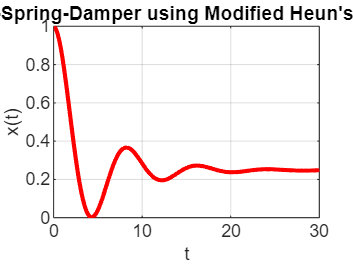

clc; clear;
F0 = 10; m = 30; k = 20; c = 10;
f = @(t, x, v) F0*exp(-2*pi*t/10)/m -c*v/m - k*x/m;
t0 = 0;
x0 = 1;
v0 = 0;
tf = 30;
h = 0.1;
N = round((tf - t0)/h);
t = zeros(1, N+1);
x = zeros(1, N+1);
v = zeros(1, N+1);
t(1) = t0;
x(1) = x0;
v(1) = v0; 
% Modified Heun's Method
for i = 1:N
 x_p = x(i) + 2*h*v(i);
 v_p = v(i) + 2*h*f(t(i), x(i), v(i));

 f1_current = v(i);
 f2_current = f(t(i), x(i), v(i));

 f1_predict = v_p;
 f2_predict = f(t(i+1), x_p, v_p);
 x(i+1) = x(i) + (h/2)*(f1_current + f1_predict);
 v(i+1) = v(i) + (h/2)*(f2_current + f2_predict);
 t(i+1) = t(i) + h;
end
plot(t, x, 'r', 'LineWidth', 2)
xlabel('t')
ylabel('x(t)')
title('Mass-Spring-Damper using Modified Heun''s Method')
grid on



figure;
plot(t, v, 'b', 'LineWidth', 2)
xlabel('t'); ylabel('v(t)')
title('Velocity Profile using Modified Heun''s Method')
grid on

figure;
plot(x, v, 'k', 'LineWidth', 2)
xlabel('x'); ylabel('v')
title('Phase Space Plot (x vs v)')
grid on


% 🔍 Problem Summary
% 
% You’re solving:
% mx¨+cx˙+kx=F0e−2πt/10
% mx¨+cx˙+kx=F0�e−2πt/10
% 
% Which is converted into a first-order system:
% 
% Let:
% 
%     x1=xx1�=x
% 
%     x2=x˙=vx2�=x˙=v
% 
% Then:
% {dx1dt=x2dx2dt=F0e−2πt/10m−cmx2−kmx1
% {dtdx1��=x2�dtdx2��=mF0�e−2πt/10�−mc�x2�−mk�x1��
% ✅ Modified Heun's Method Summary
% 
% This version uses predictor-corrector logic:
% 
%     Predictor: Use a double step size (2h) to get preliminary estimates.
% 
%     Corrector: Average slope using current and predicted values.
% 
% 🧠 Pseudocode
% 
% Given f(t, x, v), m, c, k, F0, initial conditions, step size h
% 
% Initialize:
%     t(1) = t0
%     x(1) = x0
%     v(1) = v0
% 
% For i = 1 to N:
%     Predictor step:
%         x_p = x(i) + 2*h*v(i)
%         v_p = v(i) + 2*h*f(t(i), x(i), v(i))
% 
%     Corrector step:
%         f1_current = v(i)
%         f2_current = f(t(i), x(i), v(i))
% 
%         f1_predict = v_p
%         f2_predict = f(t(i+1), x_p, v_p)
% 
%         x(i+1) = x(i) + (h/2)*(f1_current + f1_predict)
%         v(i+1) = v(i) + (h/2)*(f2_current + f2_predict)
% 
%     t(i+1) = t(i) + h
% 
% 🧪 Dry Run (First Step Only)
% 
% Let’s walk through the first step:
% 
%     Given: x0=1x0�=1, v0=0v0�=0, t0=0t0�=0
% 
%     Parameters: m=30,c=10,k=20,F0=10m=30,c=10,k=20,F0�=10, h=0.1h=0.1
% 
% Step 1
% f(t0,x0,v0)=10⋅e030−1030⋅0−2030⋅1=1030−2030=−1030=−0.3333
% f(t0�,x0�,v0�)=3010⋅e0�−3010�⋅0−3020�⋅1=3010�−3020�=−3010�=−0.3333
% 
%     Predictor:
% 
%         xp=1+2∗0.1∗0=1xp�=1+2∗0.1∗0=1
% 
%         vp=0+2∗0.1∗(−0.3333)=−0.0667vp�=0+2∗0.1∗(−0.3333)=−0.0667
% 
%     Predictor Function:
%     f(t1,xp,vp)=10e−2π∗0.1/1030−1030(−0.0667)−2030(1)≈−0.3262
%     f(t1�,xp�,vp�)=3010e−2π∗0.1/10�−3010�(−0.0667)−3020�(1)≈−0.3262
% 
%     Corrector:
%     x(2)=1+0.05∗(0+(−0.0667))=0.9967v(2)=0+0.05∗(−0.3333−0.3262)=−0.03298
%     x(2)=1+0.05∗(0+(−0.0667))=0.9967v(2)=0+0.05∗(−0.3333−0.3262)=−0.03298

## Modified Heun's PC

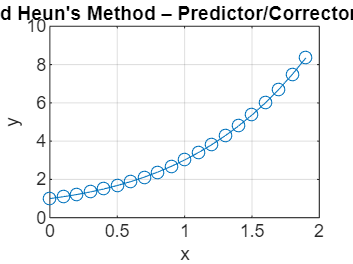

% Define the ODE function
f = @(x, y) x + y;  % Example: dy/dx = x + y

% Parameters
x0 = 0;
y0 = 1;
h = 0.1;
Nt = 20;        % Number of time steps
m = 3;          % Number of corrector iterations

% Initialize
x = x0:h:x0 + h*(Nt-1);
y = zeros(1, Nt);
y(1) = y0;

% Main loop
for i = 1:Nt-1
    % Predictor
    y0_pred = y(i) + f(x(i), y(i)) * 2 * h;

    % Predictor modifier
    y0_mod = y0_pred + (4/5) * (y(i) - y0_pred);

    % Corrector iterations
    yi_corr = y(i);  % Initial guess for y_i+1^m
    for j = 1:m
        yi_corr = y(i) + (f(x(i), y(i)) + f(x(i+1), yi_corr)) * h / 2;
    end

    % Corrector modifier
    y(i+1) = yi_corr - (1/5) * (yi_corr - y0_mod);
end

% Plot result
plot(x, y, '-o')
xlabel('x'), ylabel('y')
title('Modified Heun''s Method – Predictor/Corrector Modifier')
grid on

## Adam Bashforth (3rd order)

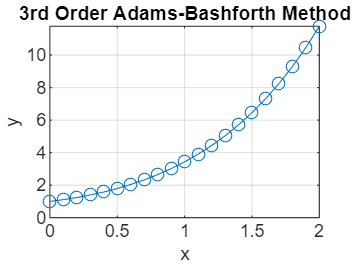

function [x, y] = adams_bashforth_3(f, x0, y0, h, N)
    % f  : function handle for dy/dx = f(x, y)
    % x0 : initial x
    % y0 : initial y
    % h  : step size
    % N  : number of steps

    x = zeros(1, N+1);
    y = zeros(1, N+1);

    % Initial conditions
    x(1) = x0;
    y(1) = y0;

    % Use RK4 to get y(2) and y(3)
    for i = 1:2
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h/2, y(i) + h*k1/2);
        k3 = f(x(i) + h/2, y(i) + h*k2/2);
        k4 = f(x(i) + h, y(i) + h*k3);
        y(i+1) = y(i) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
        x(i+1) = x(i) + h;
    end

    % Adams-Bashforth 3-step method
    for i = 3:N
        x(i+1) = x(i) + h;
        y(i+1) = y(i) + (h/12) * ( ...
            23*f(x(i), y(i)) ...
            - 16*f(x(i-1), y(i-1)) ...
            + 5*f(x(i-2), y(i-2)) );
    end
end

f = @(x, y) x + y;        % example ODE: dy/dx = x + y
x0 = 0;
y0 = 1;
h = 0.1;
N = 20;

[x, y] = adams_bashforth_3(f, x0, y0, h, N);

plot(x, y, 'o-');
xlabel('x'); ylabel('y');
title('3rd Order Adams-Bashforth Method');
grid on;

## Second Derivative IVP

function second_order_IVP_RK4
    % Parameters
    m = 1;      % mass
    c = 0.2;    % damping coefficient
    k = 2;      % spring constant
    F0 = 1;     % force amplitude
    omega = 1;  % frequency

    % Initial conditions
    t0 = 0;
    x0 = 0;     % initial position
    v0 = 1;     % initial velocity
    h = 0.01;   % step size
    tf = 10;    % final time
    N = floor((tf - t0)/h);

    % Preallocate arrays
    t = zeros(1, N+1);
    x = zeros(1, N+1);
    v = zeros(1, N+1);

    % Initial values
    t(1) = t0;
    x(1) = x0;
    v(1) = v0;

    % Define the system of ODEs
    f1 = @(t, x, v) v;
    f2 = @(t, x, v) (F0*sin(omega*t) - c*v - k*x)/m;

    % RK4 loop
    for i = 1:N
        t(i+1) = t(i) + h;

        k1x = h * f1(t(i), x(i), v(i));
        k1v = h * f2(t(i), x(i), v(i));

        k2x = h * f1(t(i) + h/2, x(i) + k1x/2, v(i) + k1v/2);
        k2v = h * f2(t(i) + h/2, x(i) + k1x/2, v(i) + k1v/2);

        k3x = h * f1(t(i) + h/2, x(i) + k2x/2, v(i) + k2v/2);
        k3v = h * f2(t(i) + h/2, x(i) + k2x/2, v(i) + k2v/2);

        k4x = h * f1(t(i) + h, x(i) + k3x, v(i) + k3v);
        k4v = h * f2(t(i) + h, x(i) + k3x, v(i) + k3v);

        x(i+1) = x(i) + (k1x + 2*k2x + 2*k3x + k4x)/6;
        v(i+1) = v(i) + (k1v + 2*k2v + 2*k3v + k4v)/6;
    end

    % Plot results
    plot(t, x, 'b', 'LineWidth', 1.5);
    hold on;
    plot(t, v, 'r--', 'LineWidth', 1.2);
    legend('Displacement x(t)', 'Velocity v(t)');
    xlabel('Time t'); ylabel('Values');
    title('Second Order IVP Solved with RK4');
    grid on;
end

## Boundary Value Problem (Shooting Method)

function shooting_linear_bvp
    % Parameters
    a = 0; b = 1;             % interval
    alpha = 1; beta = 2;      % boundary conditions
    h = 0.01;                 % step size
    N = (b - a)/h;

    % Define ODE: y'' = -2y' + 3y + x
    f = @(x, y1, y2) -2*y2 + 3*y1 + x;

    % Initial guesses for y'(a)
    s1 = 0; s2 = 1;

    % First solve with s1
    [x, y1_1] = rk4_system(a, alpha, s1, h, N, f);
    F1 = y1_1(end) - beta;

    % Second solve with s2
    [~, y1_2] = rk4_system(a, alpha, s2, h, N, f);
    F2 = y1_2(end) - beta;

    % Secant iterations
    tol = 1e-6;
    max_iter = 100;
    for iter = 1:max_iter
        s3 = s2 - F2*(s2 - s1)/(F2 - F1);
        [x, y1_3] = rk4_system(a, alpha, s3, h, N, f);
        F3 = y1_3(end) - beta;

        if abs(F3) < tol
            fprintf('Converged in %d iterations\n', iter);
            break;
        end

        % Update
        s1 = s2; F1 = F2;
        s2 = s3; F2 = F3;
    end

    % Plot result
    plot(x, y1_3, 'b-', 'LineWidth', 1.5);
    xlabel('x'); ylabel('y(x)');
    title('Solution using Shooting Method');
    grid on;
end

% RK4 solver for the system
function [x, y1] = rk4_system(a, y1_0, y2_0, h, N, f)
    x = a:h:(a + N*h);
    y1 = zeros(1, N+1);
    y2 = zeros(1, N+1);
    y1(1) = y1_0;
    y2(1) = y2_0;

    for i = 1:N
        k1_1 = h * y2(i);
        k1_2 = h * f(x(i), y1(i), y2(i));

        k2_1 = h * (y2(i) + 0.5 * k1_2);
        k2_2 = h * f(x(i) + 0.5*h, y1(i) + 0.5*k1_1, y2(i) + 0.5*k1_2);

        k3_1 = h * (y2(i) + 0.5 * k2_2);
        k3_2 = h * f(x(i) + 0.5*h, y1(i) + 0.5*k2_1, y2(i) + 0.5*k2_2);

        k4_1 = h * (y2(i) + k3_2);
        k4_2 = h * f(x(i) + h, y1(i) + k3_1, y2(i) + k3_2);

        y1(i+1) = y1(i) + (k1_1 + 2*k2_1 + 2*k3_1 + k4_1)/6;
        y2(i+1) = y2(i) + (k1_2 + 2*k2_2 + 2*k3_2 + k4_2)/6;
    end
end


## Shooting method non-linear

First guess z1 = -1100 gives T(0.5) = 516.5847
Second guess z2 = -1000 gives T(0.5) = 581.6615
Iteration 1: z = -1320.6387, T(0.5) = 378.607
Iteration 2: z = -1329.4925, T(0.5) = 373.2092
Iteration 3: z = -1329.8232, T(0.5) = 373.0078
Iteration 4: z = -1329.8355, T(0.5) = 373.0003
Iteration 5: z = -1329.836, T(0.5) = 373
Converged after 6 iterations
Final slope guess: dT/dx(0) = -1329.836


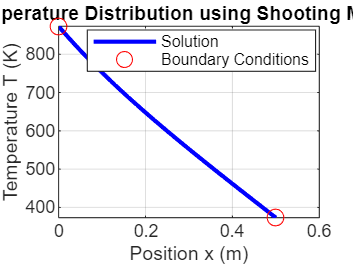

clc; clear;
shootingMethod_NonLinearBVP();

function shootingMethod_NonLinearBVP()
 k = 10;
 hr = 5e-8;
 hc = 1;
 T_inf = 298;
 x_start = 0;
 x_end = 0.5;
 dx = 0.01;
 x = x_start:dx:x_end;
 n = length(x);
 T_left = 873;
 T_right = 373;
 z1 = -1100;
 z2 = -1000;
 f = @(x, y) [y(2);
 (hr*(y(1)^4 - T_inf^4) + hc*(y(1) - T_inf))/k];

 [~, T1] = rk4_system_1(f, x_start, [T_left; z1], x, n);
 [~, T2] = rk4_system_1(f, x_start, [T_left; z2], x, n);

 disp(['First guess z1 = ', num2str(z1), ' gives T(0.5) = ', num2str(T1(1,end))]);
 disp(['Second guess z2 = ', num2str(z2), ' gives T(0.5) = ', num2str(T2(1,end))]);
 max_iter = 10;
 tol = 1e-6;
 for i = 1:max_iter
 if abs(T2(1,end) - T1(1,end)) < 1e-12
 error('Division by zero detected in interpolation step. Adjust initial guesses.');
 end
 z_next = z1 + (z2 - z1) * (T_right - T1(1,end)) / (T2(1,end) - T1(1,end));
 [~, T_new] = rk4_system_1(f, x_start, [T_left; z_next], x, n);
 if abs(T_new(1,end) - T_right) < tol
 disp(['Converged after ', num2str(i), ' iterations']);
 disp(['Final slope guess: dT/dx(0) = ', num2str(z_next)]);
 break;
 end
 if (T_new(1,end) - T_right) * (T1(1,end) - T_right) < 0
 z2 = z_next;
 T2 = T_new;
 else
 z1 = z_next;
 T1 = T_new;
 end
 disp(['Iteration ', num2str(i), ': z = ', num2str(z_next), ', T(0.5) = ', num2str(T_new(1,end))]);
 end
 figure;
 plot(x, T_new(1,:), 'b-', 'LineWidth', 2);
 hold on;
 plot([x_start, x_end], [T_left, T_right], 'ro', 'MarkerSize', 8);
 xlabel('Position x (m)');
 ylabel('Temperature T (K)');
 title('Temperature Distribution using Shooting Method');
 grid on;
 legend('Solution', 'Boundary Conditions', 'Location', 'best');
end
function [x, y] = rk4_system_1(f, x0, y0, x_array, n)
 y = zeros(length(y0), n);
 x = x_array;
 y(:,1) = y0;
 for i = 1:n-1
 h = x(i+1) - x(i);
 k1 = f(x(i), y(:,i));
 k2 = f(x(i) + h/2, y(:,i) + h*k1/2);
 k3 = f(x(i) + h/2, y(:,i) + h*k2/2);
 k4 = f(x(i) + h, y(:,i) + h*k3);
 y(:,i+1) = y(:,i) + h*(k1 + 2*k2 + 2*k3 + k4)/6;
 end
end 

## Eigenvalue problem: Power Method

clc; clear;
A = [1 5 2 3 1;
 5 5 2 1 4;
 2 2 1 4 4;
 3 1 4 1 5;
 1 4 4 5 3];
n = size(A, 1);
eigenvalues = zeros(n, 1);
eigenvectors = zeros(n, n);
A_deflated =A;
for k = 1:n
 fprintf('\nFinding eigenpair %d:\n', k);
 [lambda, v] = powerMethod(A_deflated);
 eigenvalues(k) = lambda;
 eigenvectors(:, k) = v;
 fprintf('Eigenvalue %d: %.6f\n', k, lambda);
 fprintf('Eigenvector %d: [%.6f, %.6f, %.6f, %.6f, %.6f]^T\n', k, v);

 if k < n
 P = eye(n) - (v * v');
 A_deflated = P * A_deflated * P;
 end
end


Finding eigenpair 1:


Eigenvalue 1: 14.774455


Eigenvector 1: [0.393391, 0.539396, 0.427634, 0.347910, 0.500383]^T



Finding eigenpair 2:


Eigenvalue 2: 2.963067


Eigenvector 2: [0.208544, 0.720759, -0.486809, -0.147759, -0.422137]^T



Finding eigenpair 3:


Eigenvalue 3: -4.105118


Eigenvector 3: [0.613178, -0.296996, -0.485550, -0.297535, 0.459913]^T



Finding eigenpair 4:


Eigenvalue 4: -2.387187


Eigenvector 4: [-0.208046, -0.061482, -0.556470, 0.786171, 0.158789]^T



Finding eigenpair 5:


Eigenvalue 5: -0.245217


Eigenvector 5: [0.618451, -0.312366, 0.186354, 0.387988, -0.578518]^T


fprintf('\nAll eigenvalues: \n');


All eigenvalues: 


for i = 1:n
 fprintf('λ%d = %.6f\n', i, eigenvalues(i));
end

λ1 = 14.774455
λ2 = 2.963067
λ3 = -4.105118
λ4 = -2.387187
λ5 = -0.245217


fprintf('\nVerification of eigenpairs (showing |A*v - λ*v| for each):\n');


Verification of eigenpairs (showing |A*v - λ*v| for each):


for i = 1:n
 residual = norm(A * eigenvectors(:,i) - eigenvalues(i) * eigenvectors(:,i));
 fprintf('Eigenpair %d residual: %.8f\n', i, residual);
end

Eigenpair 1 residual: 1.35057768
Eigenpair 2 residual: 2.86843913
Eigenpair 3 residual: 1.74618423
Eigenpair 4 residual: 2.85192212
Eigenpair 5 residual: 0.30051184


function [lambda, x] = powerMethod(A)
 n = size(A, 1);
 x0 = rand(n, 1);
 x0 = x0 / norm(x0);
 maxIter = 1;
 tol = 1e-8;
 iter = 0;
 lambdaPrev = 0;

 while iter < maxIter
 dummy = A * x0;
 [~, ind] = max(abs(dummy));
 lambda = dummy(ind);
 x = dummy / lambda;
 err = abs((lambda - lambdaPrev) / lambda) * 100;
 lambdaPrev = lambda;
 x0 = x;
 iter = iter + 1;
 if err < tol
 fprintf('Converged after %d iterations\n', iter);
 break;
 end
 end
 x = x / norm(x);
 lambda = x' * A * x;
end 

## Polynomial Method

% Parameters
L = 1;              % Length of the domain
n = 10;             % Number of interior points
h = L / (n + 1);    % Step size

% Construct tridiagonal matrix A such that A*y = 0 gives the polynomial form
main_diag = 2 * ones(n, 1);       % Main diagonal
off_diag  = -1 * ones(n-1, 1);    % Off diagonals

% Construct the matrix A
A = diag(main_diag) + diag(off_diag, 1) + diag(off_diag, -1);

% Convert it to polynomial form: (2 - β^2 h^2) is on diagonal
% Let λ = β^2 h^2, then eigenvalues of A = 2 - λ => λ = 2 - eigenvalue(A)

% Solve eigenvalue problem
eigenvalues = eig(A);             % Eigenvalues of matrix A
lambda = 2 - eigenvalues;         % λ = 2 - eigenvalue
beta_sq = lambda / h^2;           % β^2 = λ / h^2
beta = sqrt(beta_sq);            % Get β values

% Display β values (only real ones)
beta_real = beta(imag(beta) == 0); 
disp('Real values of beta:');

Real values of beta:


disp(beta_real);

   15.2380
   14.2683
   12.5887
   10.0265
    5.8686



## ODE Additonal codes 

if unable to find in above,

RK1 EULERMETHOD

clc; clear; close all;

% Define the function dy/dx = f(x, y)
f = @(x, y) -2*y;  % Example ODE

% Initial conditions
x0 = 0;  % Initial x
y0 = 1;  % Initial y
xf = 2;  % Final x
N = 20;  % Number of steps

% Step size
h = (xf - x0) / N;
x = x0:h:xf;  % Create x values

% Exact solution for comparison
y_exact = exp(-2*x);

% Euler method initialization
y = zeros(size(x));
y(1) = y0;  % Initial condition

% Euler method loop
for i = 1:N
    y(i+1) = y(i) + h * f(x(i), y(i));
end

% Compute absolute error at each step
error = abs(y - y_exact);

% Plot solutions
figure;
plot(x, y_exact, 'r-', 'LineWidth', 2); hold on;
plot(x, y, 'bo-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('Euler Method vs. Exact Solution');
legend('Exact Solution', 'Euler Approximation');
grid on;

% Plot error
figure;
plot(x, error, 'm-o', 'LineWidth', 2);
xlabel('x'); ylabel('Error');
title('Absolute Error at Each Step');
grid on;

% Study global error vs. step size
step_sizes = logspace(-3, -1, 10);  % Different step sizes
global_errors = zeros(size(step_sizes));

for j = 1:length(step_sizes)
    h_test = step_sizes(j);
    x_test = x0:h_test:xf;
    y_test = zeros(size(x_test));
    y_test(1) = y0;
    
    for i = 1:length(x_test)-1
        y_test(i+1) = y_test(i) + h_test * f(x_test(i), y_test(i));
    end

    % Compute global error at final step
    global_errors(j) = abs(y_test(end) - exp(-2*xf));
end

% Plot global error vs. step size
figure;
loglog(step_sizes, global_errors, 'k-o', 'LineWidth', 2);
xlabel('Step Size h');
ylabel('Global Error');
title('Global Error vs. Step Size');
grid on;

RK2 IMPROVED EULER METHOD

clc; clear; close all;

% Define the function dy/dx = f(x, y)
f = @(x, y) -2*y;  % Example ODE

% Initial conditions
x0 = 0;  % Initial x
y0 = 1;  % Initial y
xf = 2;  % Final x
N = 20;  % Number of steps

% Step size
h = (xf - x0) / N;
x = x0:h:xf;  % Create x values

% Exact solution for comparison
y_exact = exp(-2*x);

% RK-2 method initialization
y = zeros(size(x));
y(1) = y0;  % Initial condition

% RK-2 loop
for i = 1:N
    k1 = f(x(i), y(i));
    k2 = f(x(i) + h/2, y(i) + (h/2) * k1);
    
    y(i+1) = y(i) + h * k2;
end

% Compute absolute error at each step
error = abs(y - y_exact);

% Display table of results
fprintf('   x       y_RK2       y_Exact      Error\n');
fprintf('------------------------------------------\n');
for i = 1:length(x)
    fprintf('%6.3f   %10.6f   %10.6f   %10.6f\n', x(i), y(i), y_exact(i), error(i));
end

% Final global error
global_error = abs(y(end) - y_exact(end));
fprintf('\nFinal Global Error: %e\n', global_error);

% Plot solutions
figure;
plot(x, y_exact, 'r-', 'LineWidth', 2); hold on;
plot(x, y, 'bo-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('RK-2 Method vs. Exact Solution');
legend('Exact Solution', 'RK-2 Approximation');
grid on;

% Plot error
figure;
plot(x, error, 'm-o', 'LineWidth', 2);
xlabel('x'); ylabel('Error');
title('Absolute Error at Each Step (RK-2)');
grid on;

RK3 

clc; clear; close all;

% Define the function dy/dx = f(x, y)
f = @(x, y) -2*y;  % Example ODE

% Initial conditions
x0 = 0;  % Initial x
y0 = 1;  % Initial y
xf = 2;  % Final x
N = 20;  % Number of steps

% Step size
h = (xf - x0) / N;
x = x0:h:xf;  % Create x values

% Exact solution for comparison
y_exact = exp(-2*x);

% RK-3 method initialization
y = zeros(size(x));
y(1) = y0;  % Initial condition

% RK-3 loop
for i = 1:N
    k1 = f(x(i), y(i));
    k2 = f(x(i) + h/2, y(i) + (h/2) * k1);
    k3 = f(x(i) + h, y(i) + h * (-k1 + 2*k2));
    
    y(i+1) = y(i) + (h/6) * (k1 + 4*k2 + k3);
end

% Compute absolute error at each step
error = abs(y - y_exact);

% Display table of results
fprintf('   x       y_RK3       y_Exact      Error\n');
fprintf('------------------------------------------\n');
for i = 1:length(x)
    fprintf('%6.3f   %10.6f   %10.6f   %10.6f\n', x(i), y(i), y_exact(i), error(i));
end

% Final global error
global_error = abs(y(end) - y_exact(end));
fprintf('\nFinal Global Error: %e\n', global_error);

% Plot solutions
figure;
plot(x, y_exact, 'r-', 'LineWidth', 2);

RK4 

clc; clear; close all;

% Define the function dy/dx = f(x, y)
f = @(x, y) -2*y;  % Example ODE

% Initial conditions
x0 = 0;  % Initial x
y0 = 1;  % Initial y
xf = 2;  % Final x
N = 20;  % Number of steps

% Step size
h = (xf - x0) / N;
x = x0:h:xf;  % Create x values

% Exact solution for comparison
y_exact = exp(-2*x);

% RK-4 method initialization
y = zeros(size(x));
y(1) = y0;  % Initial condition

% RK-4 loop
for i = 1:N
    k1 = f(x(i), y(i));
    k2 = f(x(i) + h/2, y(i) + (h/2) * k1);
    k3 = f(x(i) + h/2, y(i) + (h/2) * k2);
    k4 = f(x(i) + h, y(i) + h * k3);
    
    y(i+1) = y(i) + (h/6) * (k1 + 2*k2 + 2*k3 + k4);
end

% Compute absolute error at each step
error = abs(y - y_exact);

% Display table of results
fprintf('   x       y_RK4       y_Exact      Error\n');
fprintf('------------------------------------------\n');
for i = 1:length(x)
    fprintf('%6.3f   %10.6f   %10.6f   %10.6f\n', x(i), y(i), y_exact(i), error(i));
end

% Final global error
global_error = abs(y(end) - y_exact(end));
fprintf('\nFinal Global Error: %e\n', global_error);

% Plot solutions
figure;
plot(x, y_exact, 'r-', 'LineWidth', 2); hold on;
plot(x, y, 'bo-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('RK-4 Method vs. Exact Solution');
legend('Exact Solution', 'RK-4 Approximation');
grid on;

% Plot error
figure;
plot(x, error, 'm-o', 'LineWidth', 2);
xlabel('x'); ylabel('Error');
title('Absolute Error at Each Step (RK-4)');
grid on;

RK4 SECOND ORDER

clc; clear; close all;

% Define the system of first-order ODEs
f_y = @(x, y, u) u;          % dy/dx = u
f_u = @(x, y, u) -2*u - y;   % du/dx = -2*u - y

% Initial conditions
x0 = 0;       % Initial x
y0 = 1;       % Initial y
u0 = 0;       % Initial dy/dx

xf = 10;      % Final x
N = 100;      % Number of steps
h = (xf - x0) / N;  % Step size
x = linspace(x0, xf, N+1); % X values

% Initialize solutions
y = zeros(1, N+1);
u = zeros(1, N+1);
y(1) = y0; % Initial y
u(1) = u0; % Initial dy/dx

% RK-4 loop
for i = 1:N
    k1_y = f_y(x(i), y(i), u(i));
    k1_u = f_u(x(i), y(i), u(i));

    k2_y = f_y(x(i) + h/2, y(i) + h/2 * k1_y, u(i) + h/2 * k1_u);
    k2_u = f_u(x(i) + h/2, y(i) + h/2 * k1_y, u(i) + h/2 * k1_u);

    k3_y = f_y(x(i) + h/2, y(i) + h/2 * k2_y, u(i) + h/2 * k2_u);
    k3_u = f_u(x(i) + h/2, y(i) + h/2 * k2_y, u(i) + h/2 * k2_u);

    k4_y = f_y(x(i) + h, y(i) + h * k3_y, u(i) + h * k3_u);
    k4_u = f_u(x(i) + h, y(i) + h * k3_y, u(i) + h * k3_u);

    y(i+1) = y(i) + (h/6) * (k1_y + 2*k2_y + 2*k3_y + k4_y);
    u(i+1) = u(i) + (h/6) * (k1_u + 2*k2_u + 2*k3_u + k4_u);
end

% Plot solution
figure;
plot(x, y, 'b-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
title('Solution of y and u = dy/dx using RK-4');
grid on;


RK5 

clc; clear; close all;

% Define the system of first-order ODEs
f1 = @(x, y1, y2) y2;          % dy1/dx = y2
f2 = @(x, y1, y2) -2*y2 - y1;  % dy2/dx = -2y2 - y1

% Initial conditions
x0 = 0;       % Initial x
y1_0 = 1;     % Initial y
y2_0 = 0;     % Initial y'

xf = 10;      % Final x
N = 100;      % Number of steps
h = (xf - x0) / N;  % Step size
x = linspace(x0, xf, N+1); % X values

% Initialize solutions for RK-5
y1_RK5 = zeros(1, N+1);
y2_RK5 = zeros(1, N+1);
y1_RK5(1) = y1_0;
y2_RK5(1) = y2_0;

% RK-5 (Butcher's method) implementation
for i = 1:N
    k1_1 = h * f1(x(i), y1_RK5(i), y2_RK5(i));
    k1_2 = h * f2(x(i), y1_RK5(i), y2_RK5(i));

    k2_1 = h * f1(x(i) + h/4, y1_RK5(i) + k1_1/4, y2_RK5(i) + k1_2/4);
    k2_2 = h * f2(x(i) + h/4, y1_RK5(i) + k1_1/4, y2_RK5(i) + k1_2/4);

    k3_1 = h * f1(x(i) + h/2, y1_RK5(i) + k2_1/2, y2_RK5(i) + k2_2/2);
    k3_2 = h * f2(x(i) + h/2, y1_RK5(i) + k2_1/2, y2_RK5(i) + k2_2/2);

    k4_1 = h * f1(x(i) + 3*h/4, y1_RK5(i) + (3/16)*k1_1 + (9/16)*k3_1, y2_RK5(i) + (3/16)*k1_2 + (9/16)*k3_2);
    k4_2 = h * f2(x(i) + 3*h/4, y1_RK5(i) + (3/16)*k1_1 + (9/16)*k3_1, y2_RK5(i) + (3/16)*k1_2 + (9/16)*k3_2);

    k5_1 = h * f1(x(i) + h, y1_RK5(i) - (3/7)*k1_1 + (2/7)*k2_1 + (12/7)*k3_1 - (12/7)*k4_1, ...
                    y2_RK5(i) - (3/7)*k1_2 + (2/7)*k2_2 + (12/7)*k3_2 - (12/7)*k4_2);
    k5_2 = h * f2(x(i) + h, y1_RK5(i) - (3/7)*k1_1 + (2/7)*k2_1 + (12/7)*k3_1 - (12/7)*k4_1, ...
                    y2_RK5(i) - (3/7)*k1_2 + (2/7)*k2_2 + (12/7)*k3_2 - (12/7)*k4_2);

    % Update values
    y1_RK5(i+1) = y1_RK5(i) + (h/90) * (7*k1_1 + 32*k2_1 + 12*k3_1 + 32*k4_1 + 7*k5_1);
    y2_RK5(i+1) = y2_RK5(i) + (h/90) * (7*k1_2 + 32*k2_2 + 12*k3_2 + 32*k4_2 + 7*k5_2);
end

% RK-4 Implementation
y1_RK4 = zeros(1, N+1);
y2_RK4 = zeros(1, N+1);
y1_RK4(1) = y1_0;
y2_RK4(1) = y2_0;

for i = 1:N
    k1_1 = h * f1(x(i), y1_RK4(i), y2_RK4(i));
    k1_2 = h * f2(x(i), y1_RK4(i), y2_RK4(i));

    k2_1 = h * f1(x(i) + h/2, y1_RK4(i) + k1_1/2, y2_RK4(i) + k1_2/2);
    k2_2 = h * f2(x(i) + h/2, y1_RK4(i) + k1_1/2, y2_RK4(i) + k1_2/2);

    k3_1 = h * f1(x(i) + h/2, y1_RK4(i) + k2_1/2, y2_RK4(i) + k2_2/2);
    k3_2 = h * f2(x(i) + h/2, y1_RK4(i) + k2_1/2, y2_RK4(i) + k2_2/2);

    k4_1 = h * f1(x(i) + h, y1_RK4(i) + k3_1, y2_RK4(i) + k3_2);
    k4_2 = h * f2(x(i) + h, y1_RK4(i) + k3_1, y2_RK4(i) + k3_2);

    % Update values
    y1_RK4(i+1) = y1_RK4(i) + (1/6) * (k1_1 + 2*k2_1 + 2*k3_1 + k4_1);
    y2_RK4(i+1) = y2_RK4(i) + (1/6) * (k1_2 + 2*k2_2 + 2*k3_2 + k4_2);
end

% Plot RK-4 vs RK-5
figure;
plot(x, y1_RK4, 'r--', 'LineWidth', 2); hold on;
plot(x, y1_RK5, 'b-', 'LineWidth', 2);
xlabel('x'); ylabel('y');
legend('RK-4', 'RK-5');
title('RK-4 vs RK-5 for Second-Order ODE');
grid on;


Step Having Method

clc; clear; close all;

% Define the function f(t,y)
f = @(t, y) -2*y + 1;   % Example ODE

% Initial conditions
t0 = 0;
y0 = 1;
tf = 5;
h = 0.1;         % Initial step size
tol = 1e-4;      % Tolerance for error

% Time stepping
t = t0;
y = y0;

T = t; Y = y;

while t < tf
    % One full step
    k1 = f(t, y);
    k2 = f(t + h, y + h * k1);
    y_full = y + h/2 * (k1 + k2);
    
    % Two half steps
    h_half = h/2;
    k1 = f(t, y);
    k2 = f(t + h_half, y + h_half * k1);
    y_half1 = y + h_half/2 * (k1 + k2);
    
    k1 = f(t + h_half, y_half1);
    k2 = f(t + h, y_half1 + h_half * k1);
    y_half2 = y_half1 + h_half/2 * (k1 + k2);

    % Estimate local error
    err = abs(y_half2 - y_full);

    if err < tol
        t = t + h;
        y = y_half2;  % Accept the more accurate step
        T(end+1) = t;
        Y(end+1) = y;
    end
    
    % Adjust step size (optional)
    if err ~= 0
        h = 0.9 * h * sqrt(tol / err);  % Error control
    end
end

% Plotting
plot(T, Y, '-o'); grid on;
xlabel('t'); ylabel('y(t)');
title('Step Halving Method Solution');

Step Having Method - 2ND order Diff. Equation

clc; clear; close all;

% System of ODEs
f = @(t, y) [y(2); -2*y(2) - y(1)];

% Initial conditions
t0 = 0;
tf = 10;
y = [1; 0];  % y1 = y, y2 = dy/dt

h = 0.1;
tol = 1e-4;

t = t0;
T = t;
Y = y;

while t < tf
    % One full step
    k1 = f(t, y);
    k2 = f(t + h, y + h * k1);
    y_full = y + h/2 * (k1 + k2);
    
    % Two half steps
    h_half = h/2;
    k1 = f(t, y);
    k2 = f(t + h_half, y + h_half * k1);
    y_half1 = y + h_half/2 * (k1 + k2);
    
    k1 = f(t + h_half, y_half1);
    k2 = f(t + h, y_half1 + h_half * k1);
    y_half2 = y_half1 + h_half/2 * (k1 + k2);

    % Error estimate and step control
    err = norm(y_half2 - y_full, inf);
    if err < tol
        t = t + h;
        y = y_half2;
        T(end+1) = t;
        Y(:, end+1) = y;
    end

    % Adjust step size
    if err ~= 0
        h = 0.9 * h * sqrt(tol / err);
    end
end

% Plotting
plot(T, Y(1,:), 'b-', 'LineWidth', 2);
xlabel('t'); ylabel('y(t)');
title('Step Halving Method for 2nd Order ODE');
grid on;


Huen Method_First order Method

clc; clear; close all;

% Define parameters
h = 0.1;          % Step size
x0 = 0;          % Initial x
y0 = 1;          % Initial y
xf = 2;         % Final x
Nh = (xf - x0) / h; % Number of steps

% Define the function dy/dx = f(x, y)
f = @(x, y) -2 * y + x;  % Example ODE: dy/dx = -2y + x

% Initialization
x = x0;
y = y0;

% Arrays for storing results
X_vals = x0:h:xf;
Y_vals = zeros(size(X_vals));
Y_vals(1) = y0;

% Heun Predictor-Corrector Iteration
for i = 1:Nh
    % Predictor step (Euler)
    y_new0 = y + 2 * f(x, y) * h;
    
    % Corrector step
    y_new0 = y_new0 + (4/5) * (y - y0);
    
    y_newm = y_new0; % Initial guess
    
    % Iterative Correction
    for j = 1:Nh
        y_newm = y + (h / 2) * (f(x, y) + f(x + h, y_newm));
    end
    
    % Final Correction
    y_newm = y_newm - (1/5) * (y_newm - y_new0);
    
    % Update values
    x = x + h;
    y = y_newm;
    
    % Store results
    Y_vals(i+1) = y;
end

% Exact solution (if known)
exact_sol = @(x) (x - 2 + 3 * exp(-2*x)); % Example exact solution for comparison

% Plot Results
figure;
plot(X_vals, Y_vals, 'bo-', 'LineWidth', 1.5); hold on;
plot(X_vals, exact_sol(X_vals), 'r--', 'LineWidth', 1.5);
legend('Heun Predictor-Corrector', 'Exact Solution');
xlabel('x'); ylabel('y');
title("Heun's Predictor-Corrector Method");
grid on;

% Error plot
error = abs(Y_vals - exact_sol(X_vals));
figure;
semilogy(X_vals, error, 'b', 'LineWidth', 1.5);
xlabel('Nh'); ylabel('Error');
title('Error Analysis of Heun-PC');
grid on;

Huen's PredictorCorrector Method 

clc; clear; close all;

% Define parameters
h = 0.1;          % Step size
x0 = 0;          % Initial x
y1_0 = 1;        % Initial y
y2_0 = 0;        % Initial y' (dy/dx)
xf = 2;          % Final x
Nh = (xf - x0) / h; % Number of steps

% Define the system of first-order ODEs
f1 = @(x, y1, y2) y2;           % dy1/dx = y2
f2 = @(x, y1, y2) -2*y2 + x;    % dy2/dx = -2y2 + x

% Initialization
x = x0;
y1 = y1_0;
y2 = y2_0;

% Arrays for storing results
X_vals = x0:h:xf;
Y1_vals = zeros(size(X_vals));
Y2_vals = zeros(size(X_vals));
Y1_vals(1) = y1_0;
Y2_vals(1) = y2_0;

% Heun Predictor-Corrector Iteration
for i = 1:Nh
    % Predictor step (Euler)
    y1_new0 = y1 + 2 * f1(x, y1, y2) * h;
    y2_new0 = y2 + 2 * f2(x, y1, y2) * h;
    
    % Corrector step
    y1_new0 = y1_new0 + (4/5) * (y1 - y1_0);
    y2_new0 = y2_new0 + (4/5) * (y2 - y2_0);
    
    y1_newm = y1_new0; % Initial guess
    y2_newm = y2_new0;
    
    % Iterative Correction
    for j = 1:Nh
        y1_newm = y1 + (h / 2) * (f1(x, y1, y2) + f1(x + h, y1_newm, y2_newm));
        y2_newm = y2 + (h / 2) * (f2(x, y1, y2) + f2(x + h, y1_newm, y2_newm));
    end
    
    % Final Correction
    y1_newm = y1_newm - (1/5) * (y1_newm - y1_new0);
    y2_newm = y2_newm - (1/5) * (y2_newm - y2_new0);
    
    % Update values
    x = x + h;
    y1 = y1_newm;
    y2 = y2_newm;
    
    % Store results
    Y1_vals(i+1) = y1;
    Y2_vals(i+1) = y2;
end

% Exact solution (if known)
exact_sol = @(x) (x - 2 + 3 * exp(-2*x)); % Example exact solution for comparison

% Plot Results
figure;
plot(X_vals, Y1_vals, 'bo-', 'LineWidth', 1.5); hold on;
plot(X_vals, exact_sol(X_vals), 'r--', 'LineWidth', 1.5);
legend('Heun Predictor-Corrector', 'Exact Solution');
xlabel('x'); ylabel('y');
title("Heun's Predictor-Corrector Method for Second-Order ODE");
grid on;

% Error plot
error = abs(Y1_vals - exact_sol(X_vals));
figure;
semilogy(X_vals, error, 'b', 'LineWidth', 1.5);
xlabel('x'); ylabel('Error');
title('Error Analysis of Heun-PC for Second-Order ODE');
grid on;

# LIEBEMAN METHOD: ELIPTICAL PDE

% Parameters
Nx = 10;               % Number of grid points in x-direction
Ny = 10;               % Number of grid points in y-direction
dx = 0.1;              % Grid spacing in x-direction
dy = 0.1;              % Grid spacing in y-direction
x = 0:dx:dx*Nx;
y = 0:dy:dy*Ny;
[X, Y] = meshgrid(x, y); % Grid

% Initialization
T = zeros(Ny+1, Nx+1);   % Temperature matrix

% Boundary conditions
T(:, end) = 50;         % Right side (y = Ny)
T(1, :) = 0;            % Bottom side (x = 1)
T(end, :) = 100;          % Top side (x = Nx)
T(:, 1) = 75;           % left side (y = 1)
% Left side (x = 0) is already zero

% Convergence parameters
err_tol = 1e-6;
it_max = 1000;
it = 1;
err = 1;

% Iterative solution (Liebmann method)
while err > err_tol && it <= it_max
    T_old = T;
    for i = 2:Ny
        for j = 2:Nx
            T(i,j) = 0.25 * (T(i+1,j) + T(i-1,j) + T(i,j+1) + T(i,j-1)); % Gauss-Seidel update
        end
    end
    err = max(max(abs((T - T_old) ./ T)));  % Relative error
    it = it + 1;
end

% Display results
fprintf('Converged in %d iterations with final error = %e\n', it-1, err);
contourf(X, Y, T, 20); colorbar;
xlabel('x'); ylabel('y'); title('Temperature Distribution');

## DIRICHLET CONDITION - FIXED WALL TEMPERATURES


% Grid size and spacing
Nx = 50; Ny = 50;
dx = 1 / (Nx - 1); dy = 1 / (Ny - 1);

% Initialize temperature field T
T = zeros(Ny, Nx); % rows = y, columns = x

% ------------------------
% Dirichlet boundaries
% ------------------------

T(:, 1)   = 100;  % Left edge
T(:, end) = 100;  % Right edge

% ------------------------
% Neumann boundaries (dT/dy = 0 => copy neighbor)
% ------------------------

T(1, :)   = T(2, :);     % Bottom edge
T(end, :) = T(end-1, :); % Top edge

% ------------------------
% Show a few values from the center
% ------------------------

i = round(Ny / 2);
j = round(Nx / 2);

d2Tdx2 = (T(i, j+1) - 2*T(i, j) + T(i, j-1)) / dx^2;
d2Tdy2 = (T(i+1, j) - 2*T(i, j) + T(i-1, j)) / dy^2;
Laplacian = d2Tdx2 + d2Tdy2;

fprintf('Laplacian at center (i=%d, j=%d) = %.4f\n', i, j, Laplacian);

## 1D PARABOLA PDE: EXPLICIT METHOD, DIRECHLET AT BOTH ENDS

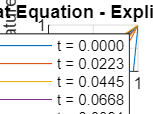


% Parameters
L = 1;            % Length of the rod
Nx = 20;          % Number of spatial points
Nt = 2005;        % Number of time steps
dx = L / (Nx - 1);
x = linspace(0, L, Nx);

alpha = 1;        % Thermal diffusivity
dt = 0.0001;      % Time step size
lambda = alpha * dt / dx^2;

% Initial and Boundary Conditions
Ti = 0;           % Initial temperature
TL = 0;           % Left boundary temperature
TH = 1;           % Right boundary temperature

% Initialize temperature matrix
T = Ti * ones(Nx, Nt);  

% Apply boundary conditions at all time steps
T(1, :) = TL;
T(end, :) = TH;

% Time stepping loop
for n = 1:Nt-1
    for i = 2:Nx-1
        T(i, n+1) = T(i, n) + lambda * (T(i+1, n) - 2*T(i, n) + T(i-1, n));
    end
end

% Plot results at selected time steps
time_indices = round(linspace(1, Nt, 10));  % Pick 10 evenly spaced time steps
figure;
hold on;
for k = 1:length(time_indices)
    plot(x, T(:, time_indices(k)));
end
xlabel('x'); ylabel('Temperature');
title('1D Heat Equation - Explicit Method');
legend(arrayfun(@(t) sprintf('t = %.4f', (t-1)*dt), time_indices, 'UniformOutput', false));
grid on;

## NEUMANN BOUNDARY CONDITION AT ONE END, DIRECHLET AT OTHER


% Parameters
L = 1;
Nx = 20; % Spatial points
Nt = 2000; % Time steps
dx = L / (Nx - 1);
x = linspace(0, L, Nx);
dt = 0.0001; % Time step size
alpha = 1; % Thermal diffusivity
lambda = alpha * dt / dx^2;

% Boundary conditions
TL = 1; % Dirichlet BC at x = L (right end)
f = 0; % Neumann condition: dT/dx = f at x = 0 (left end)

% Initialize temperature field
T = zeros(Nx, Nt);

% Apply initial Dirichlet BC at right end for all time steps
T(Nx, :) = TL;

% Time stepping
for n = 1:Nt-1
    % Internal nodes
    for i = 2:Nx-1
        T(i,n+1) = T(i,n) + lambda * (T(i+1,n) - 2*T(i,n) + T(i-1,n));
    end
    
    % Neumann BC at x = 0 (left end) using second-order accuracy
    T(1,n+1) = T(1,n) + lambda * (2*T(2,n) - 2*T(1,n) + 2*f*dx);
    
    % Dirichlet BC at x = L (right end)
    T(Nx,n+1) = TL;
end

% Plotting
time_indices = round(linspace(1, Nt, 10));
figure;
hold on;
for k = 1:length(time_indices)
    plot(x, T(:, time_indices(k)));
end
xlabel('x'); ylabel('Temperature');
title('1D Transient Heat Equation with Dirichlet and Neumann BCs');
legend(arrayfun(@(t) sprintf('t = %.4f', (t-1)*dt), time_indices, 'UniformOutput', false));
grid on;

## IMPLICIT METHOD: 1D PARABOLA


function x = thomas_solver_1(A, d)
    n = length(d);
    a = [0; diag(A, -1)]; % Sub-diagonal (a_2 to a_n)
    b = diag(A); % Main diagonal
    c = [diag(A, 1); 0]; % Super-diagonal (c_1 to c_{n-1})
    
    % Forward sweep
    for i = 2:n
        w = a(i) / b(i-1);
        b(i) = b(i) - w * c(i-1);
        d(i) = d(i) - w * d(i-1);
    end
    
    % Back substitution
    x = zeros(n, 1);
    x(n) = d(n) / b(n);
    for i = n-1:-1:1
        x(i) = (d(i) - c(i) * x(i+1)) / b(i);
    end
end

% Main script
% Parameters
L = 1;
Nx = 20;
dx = L / (Nx - 1);
x = linspace(0, L, Nx);
dt = 0.0001;
Nt = 1000;
alpha = 1;
lambda = alpha * dt / dx^2;

f = 0;      % Neumann BC at x = 0 (left): dT/dx = f
TL = 1;     % Dirichlet BC at x = L (right): T = TL

% Initialize temperature field
T = zeros(Nx, Nt);

% Apply initial Dirichlet BC at x = L for all time steps
T(Nx, :) = TL;

% Set up the tridiagonal system for interior nodes
% Note: We include the Neumann boundary at i=1 in our system
main_diag = (1 + 2*lambda) * ones(Nx-1, 1);  % Including left boundary node
sub_diag = -lambda * ones(Nx-2, 1);
super_diag = -lambda * ones(Nx-2, 1);

% Build the coefficient matrix A
A = diag(main_diag) + diag(sub_diag, -1) + diag(super_diag, 1);

% Modify first row for Neumann BC at x = 0
A(1, 1) = 1 + 2*lambda;
A(1, 2) = -2*lambda;  % Second-order accurate Neumann BC

% Time-stepping loop
for n = 1:Nt-1
    % Construct right-hand side B (all interior nodes + left boundary)
    B = T(1:Nx-1, n);
    
    % Modify for Neumann BC at x = 0
    B(1) = B(1) + 2*lambda*f*dx;  % Add the Neumann boundary term
    
    % Modify for Dirichlet BC at x = L
    B(end) = B(end) + lambda*TL;  % Add contribution from right boundary
    
    % Solve linear system
    T_new = thomas_solver_1(A, B);
    
    % Update temperature field
    T(1:Nx-1, n+1) = T_new;
    
    % Dirichlet BC at x = L
    T(Nx, n+1) = TL;
end

% Plot results
time_indices = round(linspace(1, Nt, 10));
figure; hold on;
for k = 1:length(time_indices)
    plot(x, T(:, time_indices(k)));
end
xlabel('x'); ylabel('Temperature');
title('1D Implicit Heat Equation (Neumann at x=0, Dirichlet at x=L)');
legend(arrayfun(@(t) sprintf('t = %.2f', (t-1)*dt), time_indices, 'UniformOutput', false));
grid on;

## EXPLICIT 2D PARABOLA

% Parameters
Lx = 1; Ly = 1;
Nx = 21; Ny = 21;
dx = Lx / (Nx - 1);
dy = Ly / (Ny - 1);

T_init = 20;
T_top = 100;
T_bottom = 0;
T_left = 50;

alpha = 0.15;
q_dot = 250;

dt = 0.001;
t_end = 0.25;
Nt = round(t_end / dt) + 1;

lambda = alpha * dt / dx^2;

% Initialize temperature matrices
T = T_init * ones(Nx, Ny);
Tmat = zeros(Nx, Ny, Nt);
Tmat(:, :, 1) = T;

% Time loop
for n = 2:Nt
    T_old = T;

    % Internal nodes update
    for i = 2:Nx-1
        for j = 2:Ny-1
            T(i, j) = T_old(i, j) + lambda * ...
                (T_old(i+1, j) + T_old(i-1, j) + T_old(i, j+1) + T_old(i, j-1) ...
                - 4 * T_old(i, j)) + dt * q_dot;
        end
    end

    % Boundary Conditions
    T(1, :) = T_left;              % Left side (Dirichlet)
    T(Nx, :) = T(Nx-1, :);         % Right side (Neumann: ∂T/∂x = 0)
    T(:, 1) = T_bottom;            % Bottom side (Dirichlet)
    T(:, Ny) = T_top;              % Top side (Dirichlet)

    % Store result
    Tmat(:, :, n) = T;
end

% Surface plot animation
[X, Y] = meshgrid(0:dx:Lx, 0:dy:Ly);
figure;
for n = 1:20:Nt
    surf(X, Y, Tmat(:, :, n)')
    title(['Temperature Distribution at t = ', num2str((n-1) * dt), ' s'])
    xlabel('x [m]'); ylabel('y [m]'); zlabel('T [C]')
    zlim([0 150]);
    drawnow
end

% Contour plots every 0.05 s
contour_times = 0:0.05:t_end;
figure;
for k = 1:length(contour_times)
    n = round(contour_times(k) / dt) + 1;
    subplot(2, 3, k);
    contourf(X, Y, Tmat(:, :, n)', 20, 'LineColor', 'none');
    colorbar;
    title(['Contour at t = ', num2str(contour_times(k)), ' s']);
    xlabel('x [m]');
    ylabel('y [m]');
    axis equal tight;
end
sgtitle('Thermal Contour Plots at Different Times');

## ADI METHOD PARABOLA 2D


% Parameters
Lx = 1; Ly = 1;
Nx = 21; Ny = 21;
dx = Lx / (Nx - 1); dy = Ly / (Ny - 1);
x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);

T_init = 20;
T_top = 100;
T_bottom = 0;
T_left = 50;
alpha = 0.15;
q_dot = 250;

dt = 0.001;
t_end = 0.25;
Nt = round(t_end / dt) + 1;

lambda = alpha * dt / (2 * dx^2);

% Initial condition
T = T_init * ones(Nx, Ny);
T3D = zeros(Nx, Ny, Nt);
T3D(:, :, 1) = T;

% Construct A matrix (tridiagonal system for implicit step)
main_diag = (1 + 2 * lambda) * ones(Nx - 2, 1);
off_diag = -lambda * ones(Nx - 3, 1);
A = diag(main_diag) + diag(off_diag, 1) + diag(off_diag, -1);

% Time loop
for n = 2:Nt
    % First half step (x-direction implicit)
    T_half = T;
    for j = 2:Ny - 1
        B = zeros(Nx - 2, 1);
        for i = 2:Nx - 1
            B(i - 1) = lambda * T(i, j + 1) + ...
                      (1 - 2 * lambda) * T(i, j) + ...
                      lambda * T(i, j - 1) + ...
                      dt * q_dot / 2;
        end
        % Boundary conditions in RHS
        B(1) = B(1) + lambda * T_left;
        B(end) = B(end) + lambda * T(Nx, j);

        % Solve system
        T_half(2:Nx - 1, j) = A \ B;
    end

    % Apply Neumann on right boundary (copy from left)
    T_half(Nx, :) = T_half(Nx - 1, :);

    % Second half step (y-direction implicit)
    for i = 2:Nx - 1
        B = zeros(Ny - 2, 1);
        for j = 2:Ny - 1
            B(j - 1) = lambda * T_half(i + 1, j) + ...
                      (1 - 2 * lambda) * T_half(i, j) + ...
                      lambda * T_half(i - 1, j) + ...
                      dt * q_dot / 2;
        end
        % Boundary conditions in RHS
        B(1) = B(1) + lambda * T_bottom;
        B(end) = B(end) + lambda * T_top;

        % Solve system
        T(i, 2:Ny - 1) = A \ B;
    end

    % Apply boundary conditions
    T(1, :) = T_left;
    T(:, 1) = T_bottom;
    T(:, Ny) = T_top;
    T(Nx, :) = T(Nx - 1, :); % Neumann

    % Store result
    T3D(:, :, n) = T;
end

% Contour plots every 0.05 s
contour_times = 0:0.05:t_end;
[X, Y] = meshgrid(x, y);
figure('Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);

for k = 1:length(contour_times)
    n = round(contour_times(k) / dt) + 1;
    subplot(3, 2, k);
    contourf(X, Y, T3D(:, :, n)', 20, 'LineColor', 'none');
    colorbar;
    title(['Contour at t = ', num2str(contour_times(k)), ' s']);
    xlabel('x [m]');
    ylabel('y [m]');
    axis equal tight;
end
sgtitle('Thermal Contours using ADI Scheme');

## Solving the nonlinear parabolic PDE: dT/dt = alpha*d2T/dx2 + a*T^2



% Parameters
L = 1;                  % Length of domain
Nx = 100;               % Number of spatial grid points
dx = L / (Nx - 1);      % Spatial step size
x = linspace(0, L, Nx); % Spatial grid

alpha = 0.01;           % Diffusion coefficient
a = 1;                  % Nonlinear term coefficient

T_L = 0;                % Left boundary condition (x=0)
T_R = 0;                % Right boundary condition (x=L)

T_init = sin(pi*x);     % Initial condition

t_final = 0.5;          % Final time
dt = 0.0001;            % Time step size (small enough for stability)

% Stability check for the explicit part
if alpha*dt/dx^2 > 0.5
    warning('The explicit scheme may be unstable. Consider reducing dt.');
end

% Newton-Raphson iteration parameters
err_tol = 1e-6;         % Error tolerance
max_iter = 100;         % Maximum number of iterations

% Time steps
Nt = ceil(t_final/dt);

% Initialize temperature arrays
T = T_init(:);          % Current solution (column vector)
Tv = T;                 % Previous time step solution

% Set up matrices for the implicit solver
% A is the coefficient matrix for the linear part
A = zeros(Nx, Nx);

% Fill the tridiagonal matrix
lambda = alpha * dt / dx^2;

% Interior points (using central difference for d2T/dx2)
for i = 2:Nx-1
    A(i,i-1) = -lambda;
    A(i,i)   = 1 + 2*lambda;
    A(i,i+1) = -lambda;
end

% Boundary conditions
% Dirichlet boundary conditions at both ends
A(1,1) = 1;
A(Nx,Nx) = 1;

% Time-stepping loop
time = 0;

% Create figure for animation
figure;
h_plot = plot(x, T, 'b-', 'LineWidth', 2);
title('Nonlinear Parabolic PDE Solution');
xlabel('x');
ylabel('Temperature (T)');
axis([0 L min(T_init)-0.1 max(T_init)+0.5]);
grid on;

for step = 1:Nt
    % Store current solution as previous
    Tv = T;
    
    % Apply boundary conditions
    Tv(1) = T_L;
    Tv(Nx) = T_R;
    
    % Newton-Raphson iterations to solve the nonlinear system
    err = 1;
    iter = 0;
    T_guess = Tv;
    
    while err > err_tol && iter < max_iter
        % Compute the nonlinear term
        NL = a * T_guess.^2;  % Elementwise squaring
        
        % Set up the RHS
        RHS = Tv + dt * NL;
        RHS(1) = T_L;
        RHS(Nx) = T_R;
        
        % Compute F = A*T_guess - RHS
        F = A * T_guess - RHS;
        
        % Compute the Jacobian matrix for the nonlinear term
        J = zeros(Nx, Nx);
        for i = 2:Nx-1
            J(i,i) = 2*a*dt*T_guess(i);
        end
        
        % Total system matrix for Newton step
        dF = A + J;
        
        % Solve the linear system for the update
        delta_T = dF \ (-F);
        
        % Update the guess
        T_new = T_guess + delta_T;
        
        % Compute error
        err = max(abs((T_new - T_guess) ./ max(abs(T_guess), 1e-10)));
        
        % Update for next iteration
        T_guess = T_new;
        iter = iter + 1;
    end
    
    if iter >= max_iter
        warning(['Newton-Raphson did not converge at time step ', num2str(step)]);
    end
    
    % Update the solution
    T = T_guess;
    
    % Update time
    time = time + dt;
    
    % Update plot every 50 steps
    if mod(step, 50) == 0
        set(h_plot, 'YData', T);
        title(['Time = ', num2str(time), ' s']);
        drawnow;
    end
end

% Plot final solution
figure;
plot(x, T_init, 'r--', 'LineWidth', 1.5);
hold on;
plot(x, T, 'b-', 'LineWidth', 2);
title(['Nonlinear Parabolic PDE Solution at t = ', num2str(time), ' s']);
xlabel('x');
ylabel('Temperature (T)');
legend('Initial condition', 'Final solution');
grid on;